# **MEC4127F: Introduction to Robotics**

# Chapter 3: Orientation and angular velocity

## 3.1 Introduction

Based on our results in **Chapter 2**, we now have a means of encoding the orientation of our robot body with respect to a reference frame of interest. The rotation matrix, $\bf R$, is a useful starting point in containing orientation and also plays a pivotal role in mapping vectors between frames. However, our prior knowledge of mathematics means that we are probably more comfortable with visualising rotations using individual angles. In fact, while the rotation matrix requires 9 elements to be fully populated based on the direction cosine formulation of 


$$\begin{array}{cc}^W{\mathbf R}_B =     \left[\begin{array}{cccc}    ^W{\hat{\mathbf x}}_B & ^W{\hat{\mathbf y}}_B & ^W{\hat{\mathbf z}}_B    \\ \end{array}\right] = \left[\begin{array}{cccccccc}    \cos(\alpha_{xx}) & \cos(\alpha_{yx}) & \cos(\alpha_{zx}) \\    \cos(\alpha_{xy}) & \cos(\alpha_{yy}) & \cos(\alpha_{zy}) \\    \cos(\alpha_{xz}) & \cos(\alpha_{yz}) & \cos(\alpha_{zz})    \\ \end{array}\right],\ \end{array}$$


we actually only need to know as little as $3$ distinct values to define the orientation. This follows from the fact that an orthogonal matrix imposes $6$ constraints on the $9$-element matrix $\bf R$; $3$ from the unit-norm requirement of 


$$\begin{array}{cc}r_{11}^2+r_{21}^2+r_{31}^2=1,\\ \end{array}$$
    
$$\begin{array}{cc}    r_{12}^2+r_{22}^2+r_{32}^2=1,\\ \end{array}$$
    
$$\begin{array}{cc}    r_{13}^2+r_{23}^2+r_{33}^2=1,\\ \end{array}$$


and $3$ from the orthogonality condition of 


$$\begin{array}{cc}r_{11}r_{12}+r_{21}r_{22}+r_{31}r_{32}=0,\\ \end{array}$$
    
$$\begin{array}{cc}    r_{12}r_{13}+r_{22}r_{23}+r_{32}r_{33}=0,\\ \end{array}$$
    
$$\begin{array}{cc}    r_{11}r_{13}+r_{21}r_{23}+r_{31}r_{33}=0.\\ \end{array}$$


With $9$ unknown terms in $\bf R$ and $6$ constraints, this results in $3$ free parameters. This result should not be terribly surprising considering that we are working in a three-dimensional space with three axes. 

Note that in the special case of planar rotation, the orientation corresponding to the rotation matrix 


$$\begin{array}{ll}
{\mathbf R} 
= \left[\begin{array}{cc}    {\cos\theta & -\sin\theta \\     \sin\theta & \cos\theta    \\ \end{array}\right],
\end{array}$$


is uniquely described by the single angle $\theta$. 

### 3.1.1 Representing orientation

There are a number of different ways to represent orientation. While rotation matrices have their uses in performing vector or frame mappings, it is not always obvious what orientation is being described within the $3\times3$ matrix form. Additionally, when visualising orientation on a time-domain plot, for example to assess the attitude of a spacecraft, vector descriptions of orientation make more sense. We will also see later in this course that vector-based orientation descriptors fit better in state estimation and control design techniques.

We will consider three main methods of representing orientation as a vector in this course:

- Euler angles

- Quaternions

- Exponential coordinates

Notably, each of these approaches has relative strengths and weaknesses. The following sections will provide more information.

## 3.2 Euler angles 

Euler angles are arguably the most common representation used when describing orientation in robotics and can be used to encode/decode orientation information from the rotation matrix. In the case of capturing the frame $\{B\}$ orientation with respect to $\{W\}$, the Euler angle vector is given by


$$\begin{array}{cc}{^W\mathbf\eta_B} = \left[\begin{array}{cc}    \phi \\    \theta \\    \psi    \\ \end{array}\right],\\ \end{array}$$


which uniquely describes the relative orientation using three angles:

- roll ($\phi$), 

- pitch ($\theta$), 

- yaw ($\psi$).

These three angles have the following bounds: 

- $\{\phi,\psi\}\in[-\pi,\pi]$, 

- $\theta\in[-\frac{\pi}{2},\frac{\pi}{2}]$.

Euler angles describe a particular orientation using three disparate rotations. The basic concept is that we can construct the orientation of one reference frame relative to another by using three sequential, distinct rotations about the principal axes of one of the frames. 

### 3.2.1 Rotation sequence

In the case of the single rigid-body problem, and using our two frames of interest, $\{W\}$ and $\{B\}$, we are going to make three sequential rotations about our *current* reference frame, moving "backwards" from frame $\{W\}$, eventually to frame $\{B\}$. We begin in frame $\{W\}$with a null rotation matrix of  $\mathbf R = {\bf I}$ (our current reference frame that is attached to the robot body and $\{W\}$ are aligned). With reference to Figure 3.1, we start by first rotating about the current $z$ -axis,  $\hat{\mathbf z}_W$ , with angle $\psi$ (shown in the leftmost image).

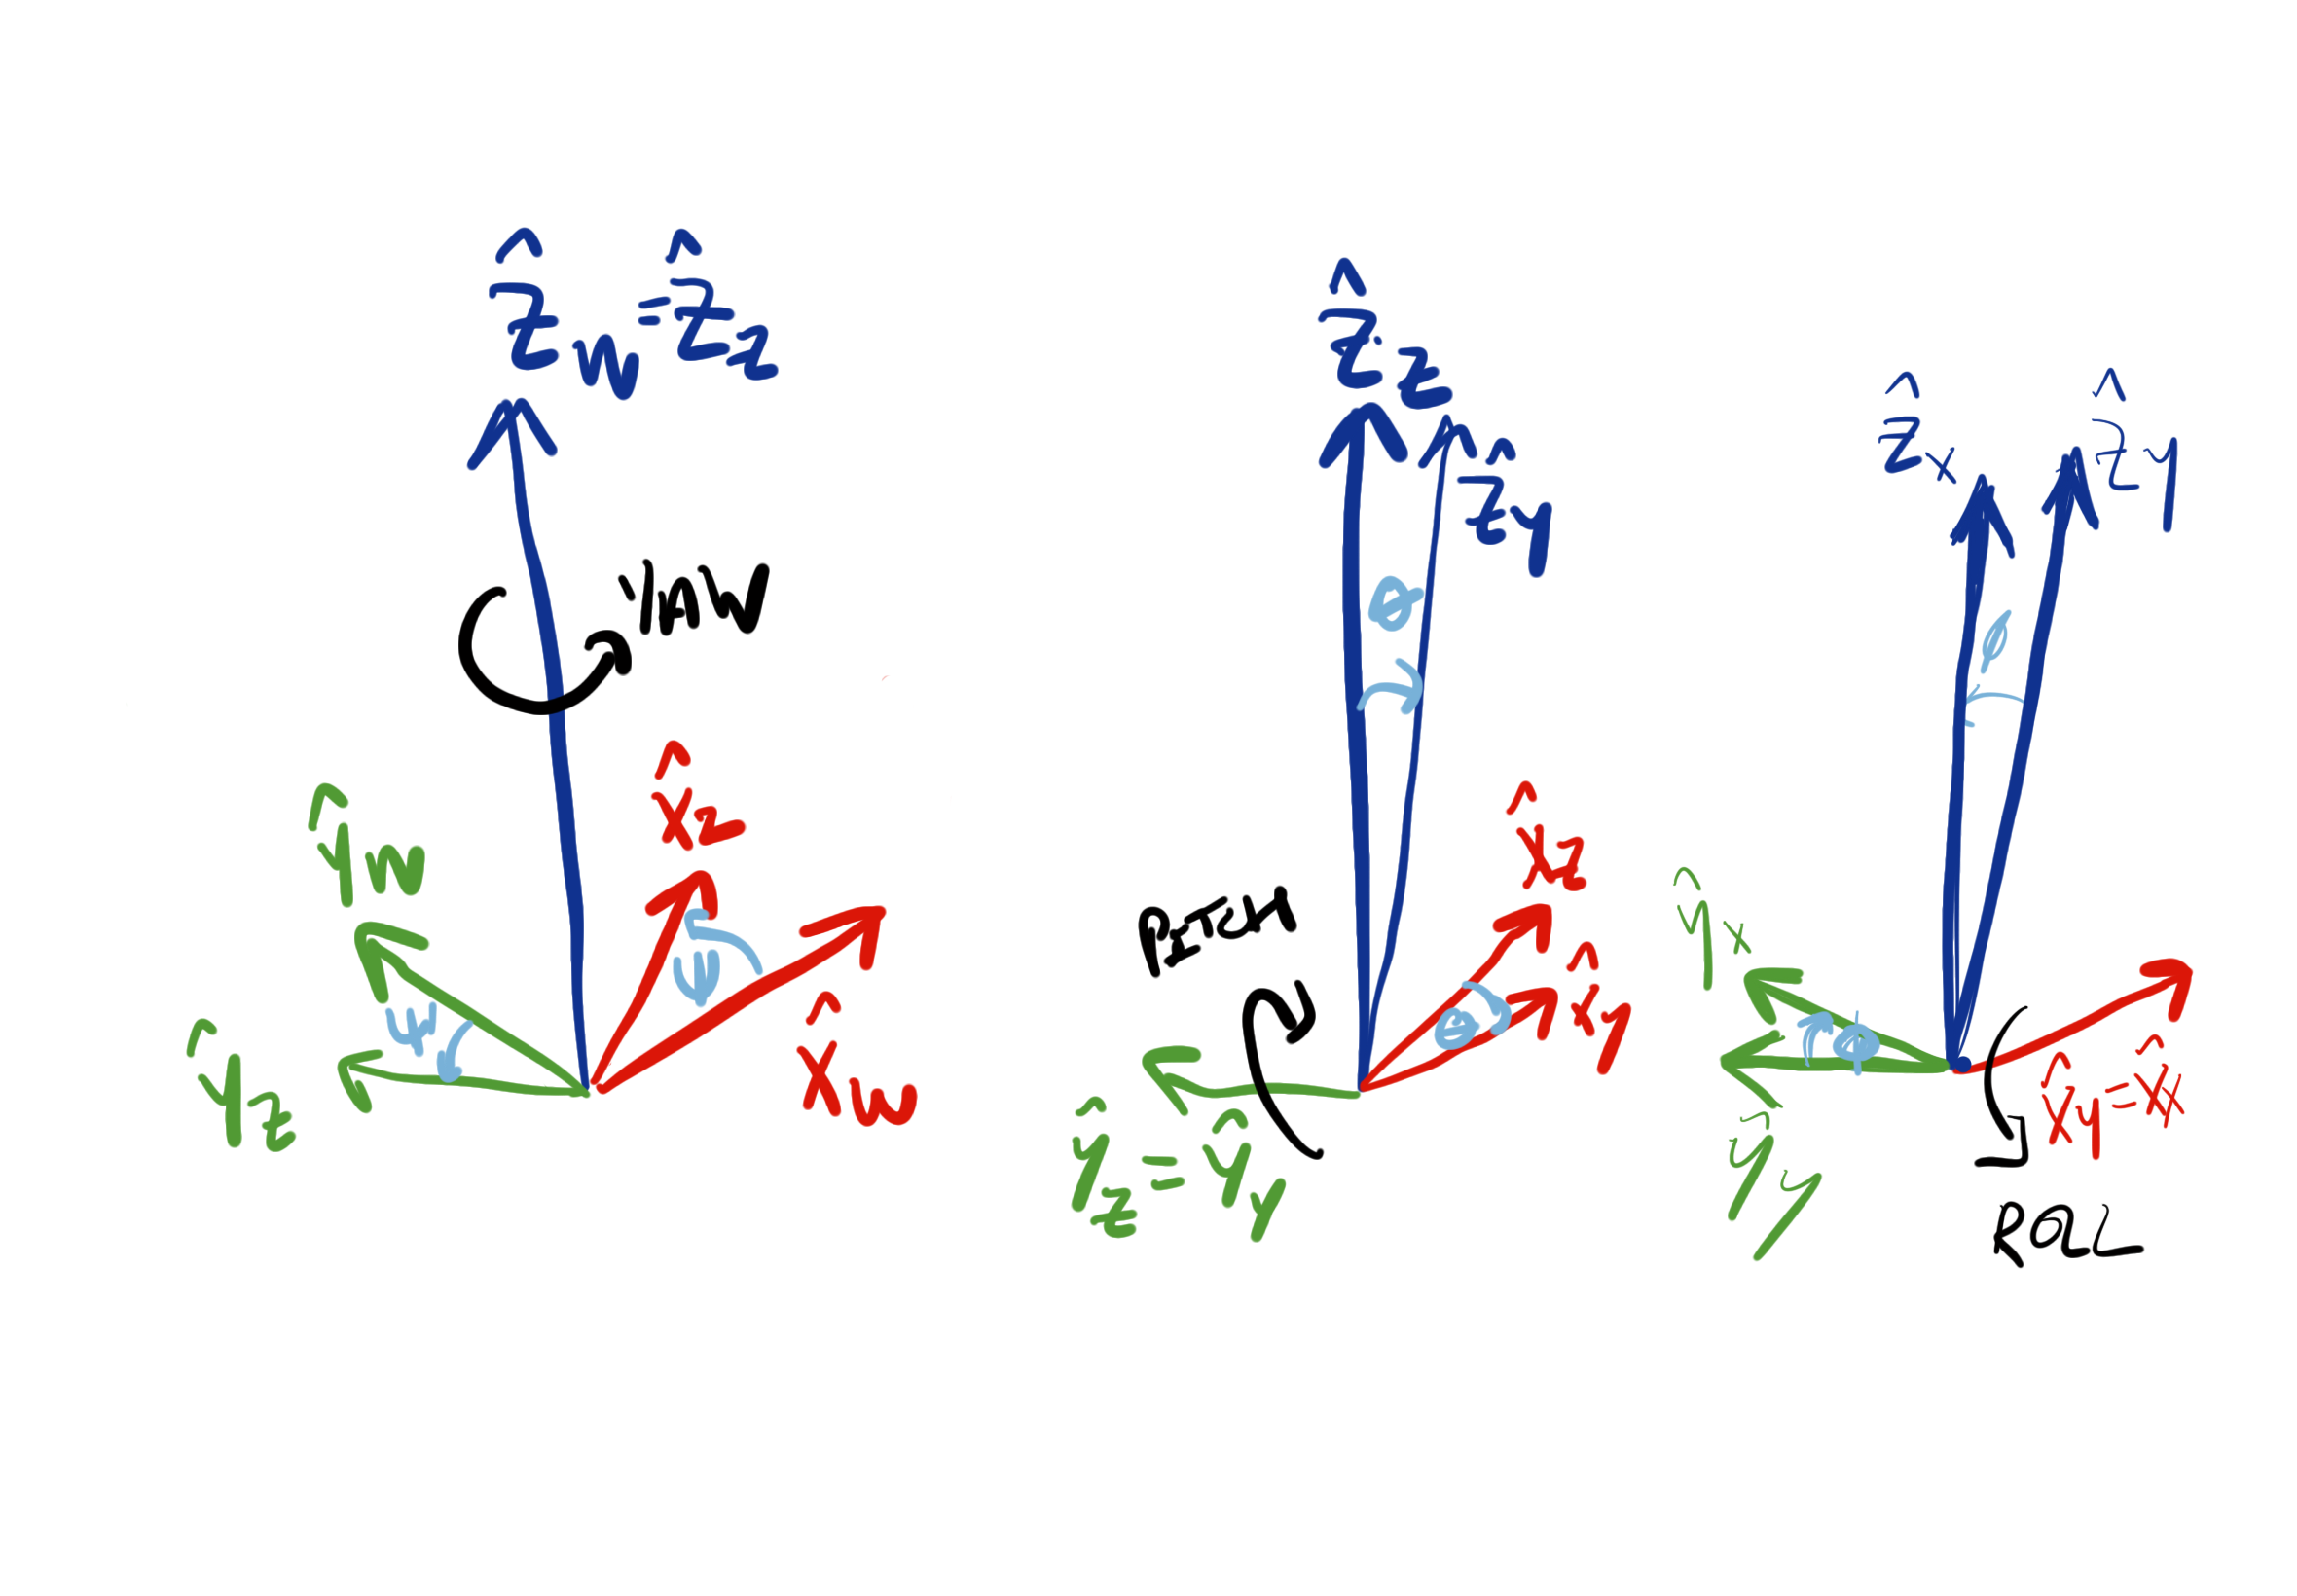

**Figure 3.1:** Intrinsic Euler ZYX rotation sequence.
 

The rotation matrix that corresponds to this rotation about  $\hat{\mathbf z}_W$, rotating from $\{W\}$ to the new frame $\{Z\}$, is 


$$\begin{array}{cc}^W{\mathbf R}_Z = \left[\begin{array}{cccccccc}    \cos{ \psi} & -\sin{ \psi} & 0 \\    \sin{ \psi } & \cos{ \psi } & 0 \\    0 & 0 & 1    \\ \end{array}\right].\\ \end{array}$$


$^W{\mathbf R}_Z$ is known as an elementary rotation and notably only affects vectors in the  $\hat{\mathbf x}_W$ - $\hat{\mathbf y}_W$ plane (the  $z$ component is unaffected). Note that we have implicitly introduced a new reference frame, $\{Z\}$, from this rotation, with the above equation describing the orientation of $\{Z\}$ relative to $\{W\}$. Following this, we then rotate about the $y$-axis of $\{Z\}$,  $\hat{\bf y}_Z$, with angle $\theta$. The incremental rotation matrix that rotates $\{Z\}$ to $\{Y\}$ is


$$\begin{array}{cc}^Z{\mathbf R}_Y = \left[\begin{array}{cccccccc}    \cos{\theta} & 0 & \sin{\theta} \\    0 & 1 & 0 \\    -\sin{\theta} & 0 & \cos{\theta}    \\ \end{array}\right].\\ \end{array}$$


We have again introduced a new reference frame, $\{Y\}$, using an elementary rotation. The final step is to rotate about  $\hat{\mathbf x}_Y$ with angle $\phi$. The corresponding incremental rotational mapping from $\{Y\}$ to $\{X\}=\{B\}$ (our body-frame of interest) is


$$\begin{array}{cc}^Y{\mathbf R}_B = \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & \cos{\phi} & -\sin{\phi} \\    0 & \sin{\phi} & \cos{\phi}    \\ \end{array}\right].\\ \end{array}$$


We can now stitch together the sequential rotations (keeping an eye on the subscripts and superscripts to aid the multiplication order) to describe our body-frame orientation, relative to the inertial-frame: 


$$\begin{array}{cc}{^W {\mathbf R}_B} = {^W {\mathbf R}_Z}{^Z {\mathbf R}_Y}{^Y {\mathbf R}_B}.\\ \end{array}$$


This representation makes use of *Z-Y-X Euler angles, *with the"Z-Y-X" term indicating the rotation order. The rotation sequence can be thought of as so-called *intrinsic,* as the three rotations are performed around one of the "new" reference frame principal axes. *Extrinsic Euler angles* by contrast result from performing three rotations about different combinations of the world-frame axes. 

The form derived above is commonly referred to as *Tait-Bryan Angles*, or nautical *angles*. That is, we first rotated about  $\hat{\mathbf z}_W$ , followed by a rotation about  $\hat{\mathbf y}_Z$ , and finishing with a rotation about  $\hat{\mathbf x}_Y$ . Explicitly, our rotation matrix, parameterised by the Z-Y-X Euler angles, is written as


$$\begin{array}{cc}^W{\mathbf R}_B =    \left[\begin{array}{cccccccc}    \cos{ \psi} & -\sin{ \psi} & 0 \\    \sin{ \psi } & \cos{ \psi } & 0 \\    0 & 0 & 1    \\ \end{array}\right]    \left[\begin{array}{cccccccc}    \cos{\theta} & 0 & \sin{\theta} \\    0 & 1 & 0 \\    -\sin{\theta} & 0 & \cos{\theta}    \\ \end{array}\right]    \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & \cos{\phi} & -\sin{\phi} \\    0 & \sin{\phi} & \cos{\phi}    \\ \end{array}\right], \end{array}$$


and after performing the matrix multiplication yields 


$$\begin{array}{cc}^W{\mathbf R}_B =    \left[\begin{array}{cccccccc}    \cos{\psi}\cos{\theta} & \cos{\psi}\sin{\theta}\sin{\phi}-\cos{\phi}\sin{\psi} & \sin{\psi}\sin{\phi}+\cos{\psi}\cos{\phi}\sin{\theta}\\    \cos{\theta}\sin{\psi} & \cos{\psi}\cos{\phi}+\sin{\psi}\sin{\theta}\sin{\phi} & \cos{\phi}\sin{\psi}\sin{\theta}-\cos{\psi}\sin{\phi} \\    -\sin{\theta} & \cos{\theta}\sin{\phi} & \cos{\phi}\cos{\theta}    \\ \end{array}\right]    .\end{array}$$


syms phi theta psi real

Rz = [cos(psi) -sin(psi) 0;
      sin(psi) cos(psi) 0;
      0          0       1];
Ry = [cos(theta)   0   sin(theta);
      0          1       0;
     -sin(theta)   0   cos(theta)];
Rx = [1     0        0;
      0 cos(phi) -sin(phi);
      0 sin(phi) cos(phi)];

R = Rz*Ry*Rx

$$R = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

While the matrix above may seem a bit overwhelming, it is important to note that we only require three variables to fully define it, namely the Euler angles - $\{ \phi, \theta, \psi \}$ , which respectively describe roll, pitch, and yaw — see Figure 3.2 for a useful mnemonic to remember the rotation axes. 

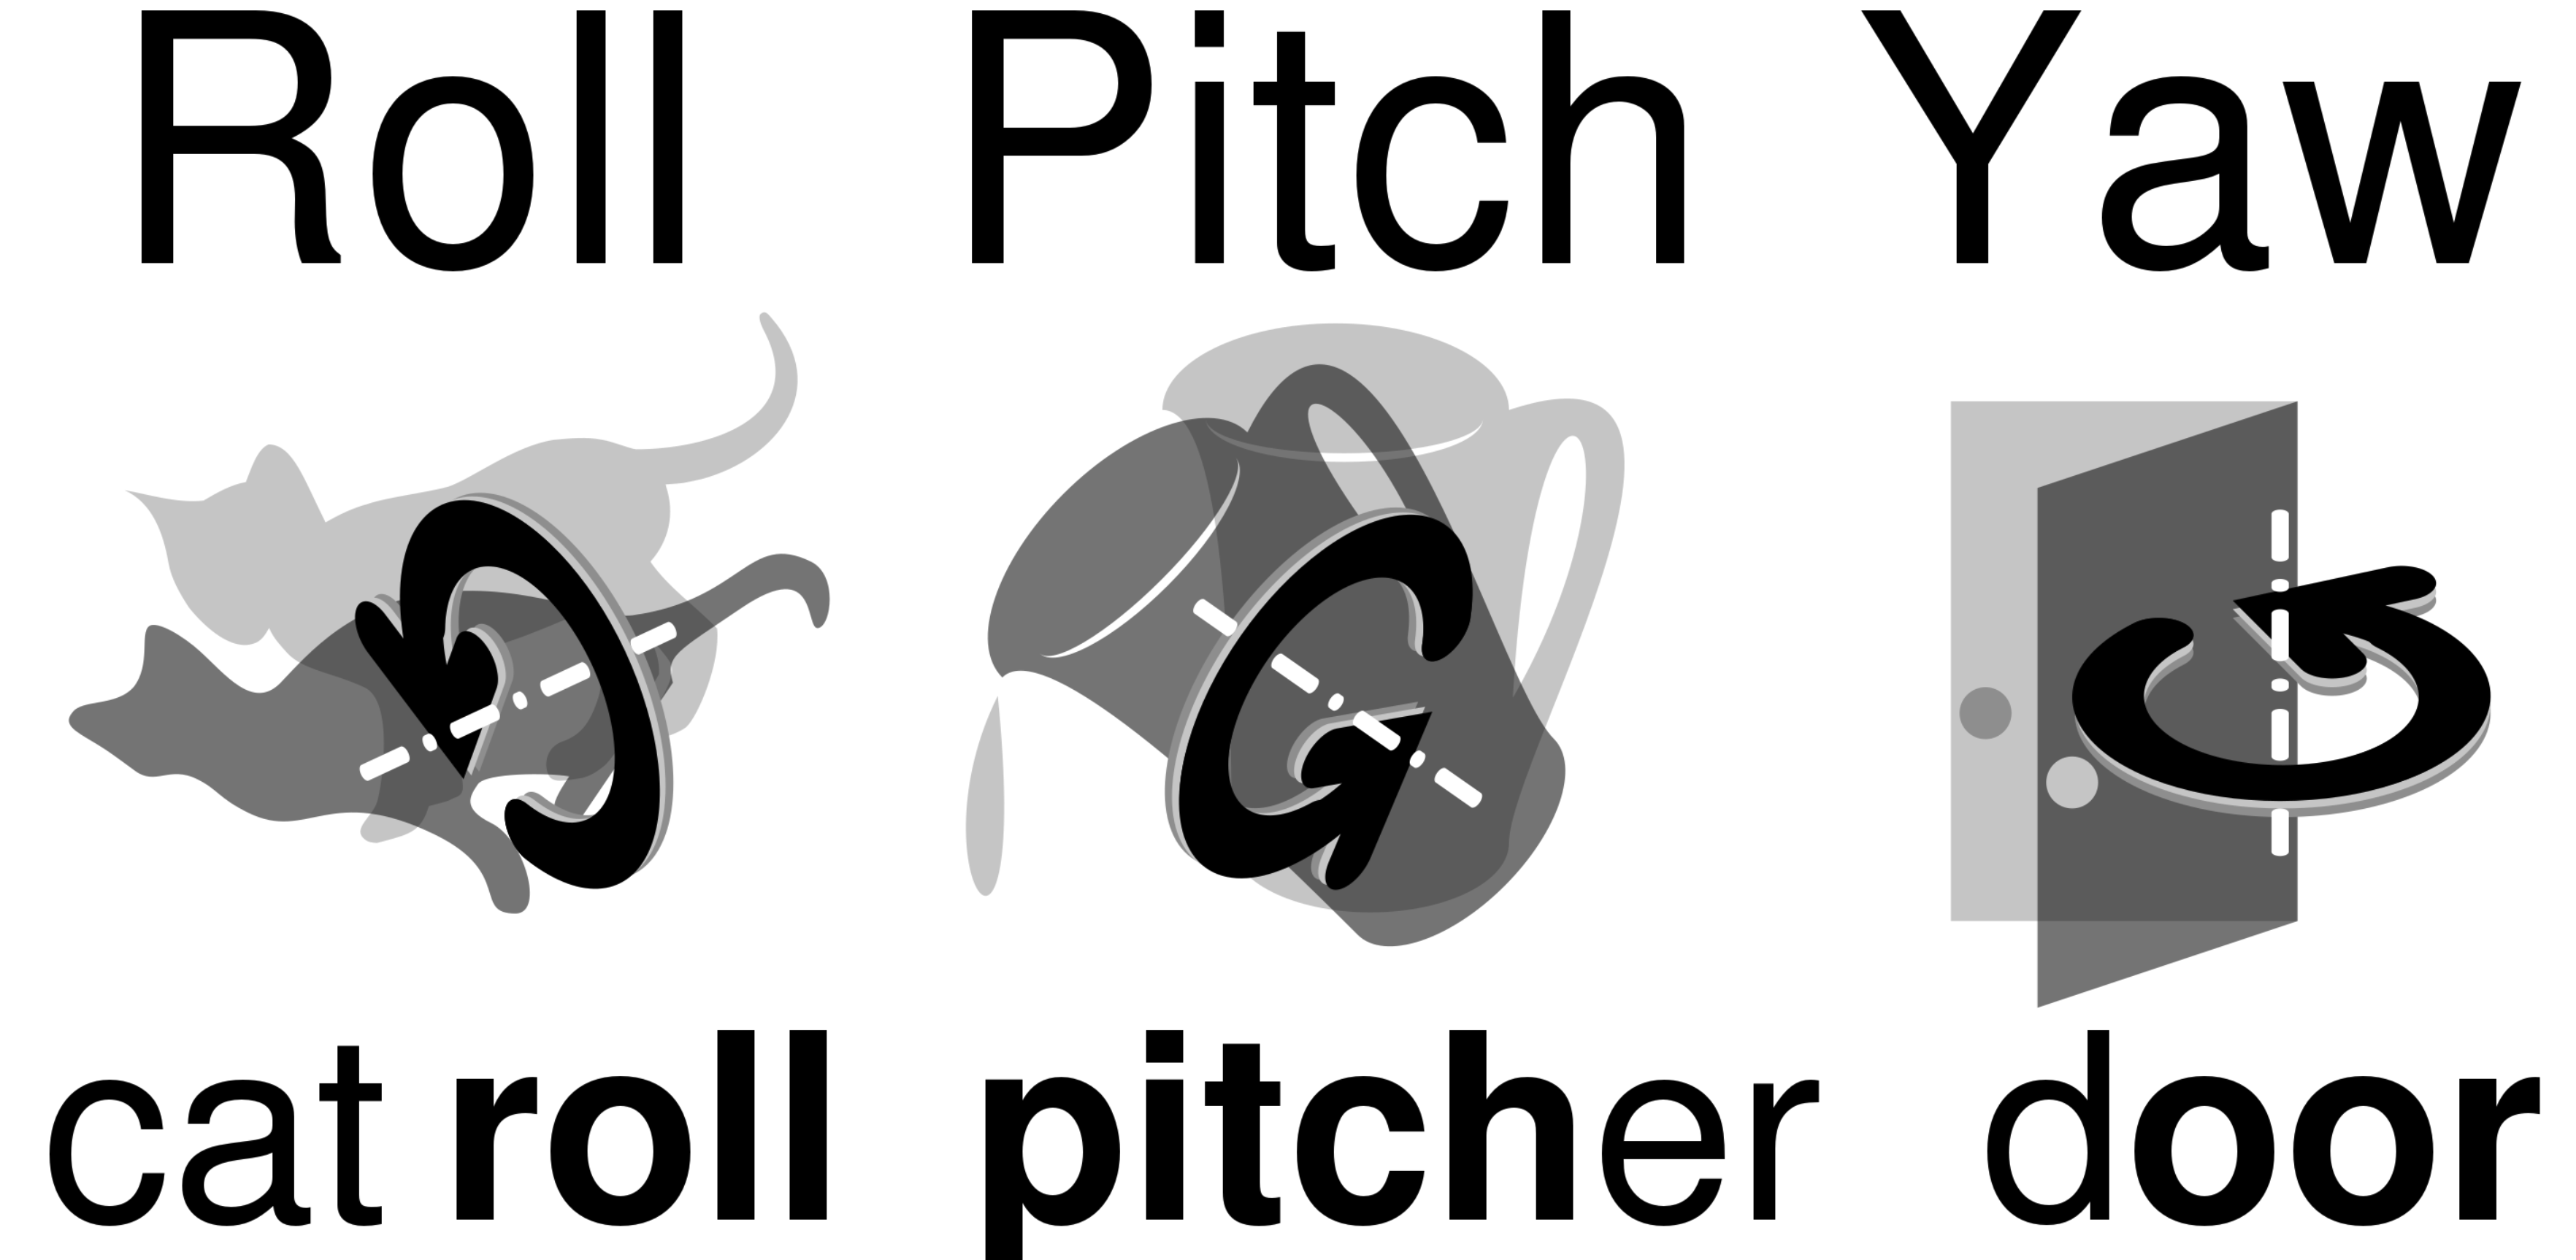

**Figure 3.2:** Mnemonics to remember the roll, pitch and yaw angle rotation axes.


The code block below can be used to visualise the workings of Euler angles in the four different frames that show the progression from $\{W\}$ to $\{B\}$, namely


$$\{W\} \rightarrow \{Z\} \rightarrow \{Y\} \rightarrow \{B\}.$$


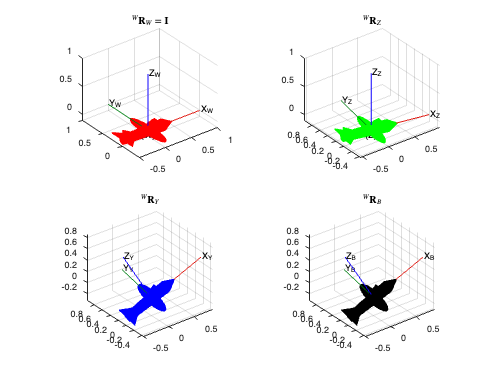

phi = 0*pi/180;
the = -30*pi/180;
psi = -10*pi/180;

Rz = [cos(psi) -sin(psi) 0;
      sin(psi) cos(psi) 0;
      0          0       1];
Ry = [cos(the)   0   sin(the);
      0          1       0;
     -sin(the)   0   cos(the)];
Rx = [1     0        0;
      0 cos(phi) -sin(phi);
      0 sin(phi) cos(phi)];

figure,hold on
subplot(2,2,1),plotTransforms([0 0 0],rotm2quat(eye(3)),"MeshFilePath",'fixedwing.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title('$^W{\bf R}_W={\bf I}$',Interpreter='latex'),grid on
subplot(2,2,2),plotTransforms([0 0 0],rotm2quat(Rz),"MeshFilePath",'fixedwing.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title('$^W{\bf R}_Z$',Interpreter='latex'),grid on
subplot(2,2,3),plotTransforms([0 0 0],rotm2quat(Rz*Ry),"MeshFilePath",'fixedwing.stl',"MeshColor","blue","FrameAxisLabels","on","FrameLabel","Y")
axis equal, title('$^W{\bf R}_Y$',Interpreter='latex'),grid on
subplot(2,2,4),plotTransforms([0 0 0],rotm2quat(Rz*Ry*Rx),"MeshFilePath",'fixedwing.stl',"MeshColor","black","FrameAxisLabels","on","FrameLabel","B")
axis equal, title('$^W{\bf R}_B$',Interpreter='latex'),grid on

While the *Z-Y-X* rotation order is fairly common in engineering (especially aeronautics and aerial robotics), we could have actually chosen from a multitude of rotation orders. Our only constraint is that we cannot rotate about the same axis sequentially, as that would be equivalent to a single rotation by the sum of the two angles. The twelve valid rotation orders are:


$$\begin{array}{cc}    XYX, XZX, YXY, YZY, ZXZ, ZYZ, XYZ, XZY, YZX, YXZ, ZXY, ZYX\\ \end{array}$$


### 3.2.2 Gimbal lock

Different industries and manufacturers will use different conventions, but it is important to note there is technically no right or wrong version. However, one crucial point to be aware of is that an Euler angle representation of orientation always exhibits a singularity when any two rotation axes are parallel or anti-parallel. This phenomenon is commonly referred to as *gimbal lock*. 

#### **Definition: Gimbal lock**

**Gimbal lock** is the loss of one degree of freedom in a three-dimensional, three-gimbal mechanism that occurs when the axes of two of the three gimbals are driven into a parallel configuration, "locking" the system into rotation in a degenerate two-dimensional space. 

For the set of Euler angle rotation orders with repeated axes (sometimes referred to as Eulerian), namely


$$\begin{array}{cc}    XYX, XZX, YXY, YZY, ZXZ, ZYZ,  \end{array}$$


gimbal lock will occur when the second angle of rotation equals zero, as this will make the first and third rotation axis align.

For the set of Euler angles with no repeated axes (sometimes referred to as Cardian), namely


$$\begin{array}{cc}    XYZ, XZY, YZX, YXZ, ZXY, ZYX,\\ \end{array}$$


gimbal lock will occur when the second angle of rotation equals $\pm 90^\circ$, as this will make the first and third rotation axis align. 

In summary, regardless of the Euler rotation convention, gimbal lock will occur when the first and third rotation axes are aligned. Physically, this means that rotations about the first and third axis cannot be differentiated apart, and are instead summed, as a result of degenerate 2D space. Figure 3.3 below gives a visualisation of gimbal lock.

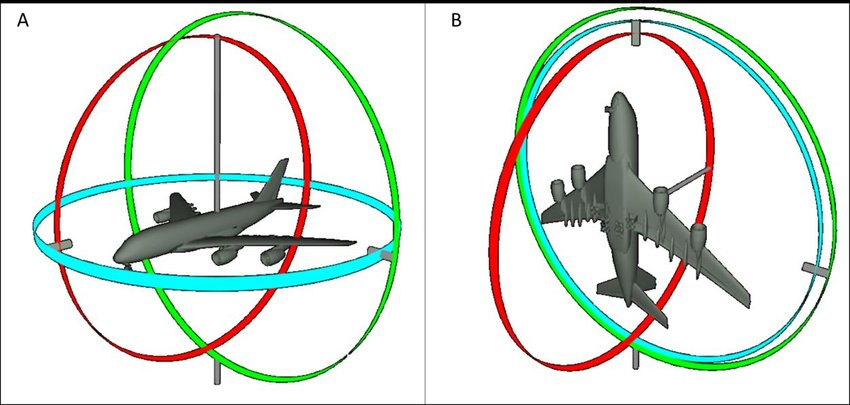

**Figure 3.3:** Visualisation of the three rotational axes (facilitated by imaginary gimbals) attached to an airplane. Left: nominal condition with none of the axes aligned. Right: Two of the gimbals become aligned causing a loss of information in one of the axes and resulting in a singularity.
 

So if you plan to use Euler angles, you need to be cognizant of how the angular behaviour is going to evolve. If the operating region contains Euler angles that cause the first and last rotation axes to become parallel, then consider re-framing how you have defined your reference frame, or use a different rotation order to circumvent the potential for gimbal lock. [This](https://www.youtube.com/watch?v=-WXfEPg8eMM&feature=youtu.b) video provides a good explanation of gimbal lock and the singularity problem. 

### 3.2.3 Extracting Euler angles

The Euler-parameterised rotation matrix shows us how to populate a rotation matrix given our Z-Y-X ordering, ${^W{\mathbf R}_B}={\mathbf R}({^W\mathbf\eta_B})$, but we can also extract Euler angle information from a rotation matrix if required:  


$$^W\mathbf\eta_B={\mathbf R}^{-1}({^W{\mathbf R}_B}).$$


We may, for example, need Euler angle information to visualise how our robot is oriented, or we may want to make use of that information within a control loop (e.g. regulating the orientation of a manipulator arm). Denoting the row $x$ and column $y$ element of the rotation matrix ${\bf R}$ as $r_{xy}$, namely


$$\begin{array}{cc}^W{\mathbf R}_B = \left[\begin{array}{cccccccc}    r_{11} & r_{12} & r_{13} \\    r_{21} & r_{22} & r_{23} \\    r_{31} & r_{32} & r_{33}    \\ \end{array}\right]=    \left[\begin{array}{cccccccc}    \cos{\psi}\cos{\theta} & \cos{\psi}\sin{\theta}\sin{\phi}-\cos{\phi}\sin{\psi} & \sin{\psi}\sin{\phi}+\cos{\psi}\cos{\phi}\sin{\theta}\\    \cos{\theta}\sin{\psi} & \cos{\psi}\cos{\phi}+\sin{\psi}\sin{\theta}\sin{\phi} & \cos{\phi}\sin{\psi}\sin{\theta}-\cos{\psi}\sin{\phi} \\    -\sin{\theta} & \cos{\theta}\sin{\phi} & \cos{\phi}\cos{\theta}    \\ \end{array}\right]    .\end{array}$$


the corresponding Euler angles can be extracted using


$$\begin{array}{cc}\phi = \arctan(\frac{r_{32}}{r_{33}})\end{array},$$



$$\begin{array}{cc}\theta = -\arcsin{r_{31},\end{array}$$



$$\begin{array}{cc}\psi = \arctan(\frac{r_{21}}{r_{11}}).\end{array}$$


Importantly, this result is only valid for *Z-Y-X* intrinsic Euler angles. 

phi = -40*pi/180;
the = 90*pi/180;
psi = -80*pi/180;

Rz = [cos(psi) -sin(psi) 0; %principle rotation about z-axis
      sin(psi) cos(psi) 0;
      0          0       1];
Ry = [cos(the)   0   sin(the);  %principle rotation about y-axis
      0          1       0;
     -sin(the)   0   cos(the)];
Rx = [1     0        0;     %principle rotation about x-axis
      0 cos(phi) -sin(phi);
      0 sin(phi) cos(phi)];
R = Rz*Ry*Rx;

phi_ = atan2( R(3,2),R(3,3) )*180/pi

phi_ = -40

theta_ = -asin( R(3,1) )*180/pi

theta_ = 90

psi_ = atan2( R(2,1),R(1,1) )*180/pi

psi_ = -80

### 3.2.4 Intrinsic and extrinsic rotations

Recall our Euler angle result of


$$\begin{array}{cc}{^W {\mathbf R}_B} = {^W {\mathbf R}_Z}{^Z {\mathbf R}_Y}{^Y {\mathbf R}_B}, \end{array}$$


which we assembled from left to right using the ordering of 


$$\{W\} \rightarrow \{Z\} \rightarrow \{Y\} \rightarrow \{B\}.$$
 

Notably, we can also think of constructing the result above, building instead from right to left, by starting in $\{B\}$ and then performing a rotation of $\phi$ about ${\hat{\bf x}_W}$, followed by a rotation of $\theta$ about $\hat{\bf y}_W$, and then finally, a rotation of $\psi$ about $\hat{\bf z}_W$. This gives us a clue about intrinsic and extrinsic rotations:

- when a frame is rotated about a vector in $\{B\}$, we should *post-multiply* the current orientation with the matrix describing the rotation,

- when a frame is rotated about a vector in $\{W\}$, we should *pre-multiply* the current orientation with the matrix describing the rotation.

#### Example: Intrinsic and extrinsic rotations

In this example the robot has a initial orientation described by 


$$\begin{array}{cc}{\mathbf R} = \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & 0 & -1 \\    0 & 1 & 0    \\ \end{array}\right]    .\end{array}$$


If the robot then experiences a rotation of $\psi$ about $\hat{\bf z}_B$, we can describe the resulting orientation as 


$$\begin{array}{cc}{\mathbf R}{\bf R}_z = \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & 0 & -1 \\    0 & 1 & 0    \\ \end{array}\right]
\left[\begin{array}{cccccccc}    \cos\psi & -\sin\psi & 0 \\    \sin\psi & \cos\psi & 0 \\    0 & 0 & 1    \\ \end{array}\right]    ,\end{array}$$


which is obtained by post-multiplying ${\bf R}$ by ${\bf R}_z$. If instead, the robot with initial orientation of ${\bf R}$ experiences a rotation of $\psi$ about $\hat{\bf z}_W$, we can describe the resulting orientation as 


$$\begin{array}{cc}{\bf R}_z{\mathbf R} = 
\left[\begin{array}{cccccccc}    \cos\psi & -\sin\psi & 0 \\    \sin\psi & \cos\psi & 0 \\    0 & 0 & 1    \\ \end{array}\right] \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & 0 & -1 \\    0 & 1 & 0    \\ \end{array}\right]   ,\end{array}$$


which is obtained by pre-multiplying ${\bf R}$ by ${\bf R}_z$. The code block below provides a visual representation of this.

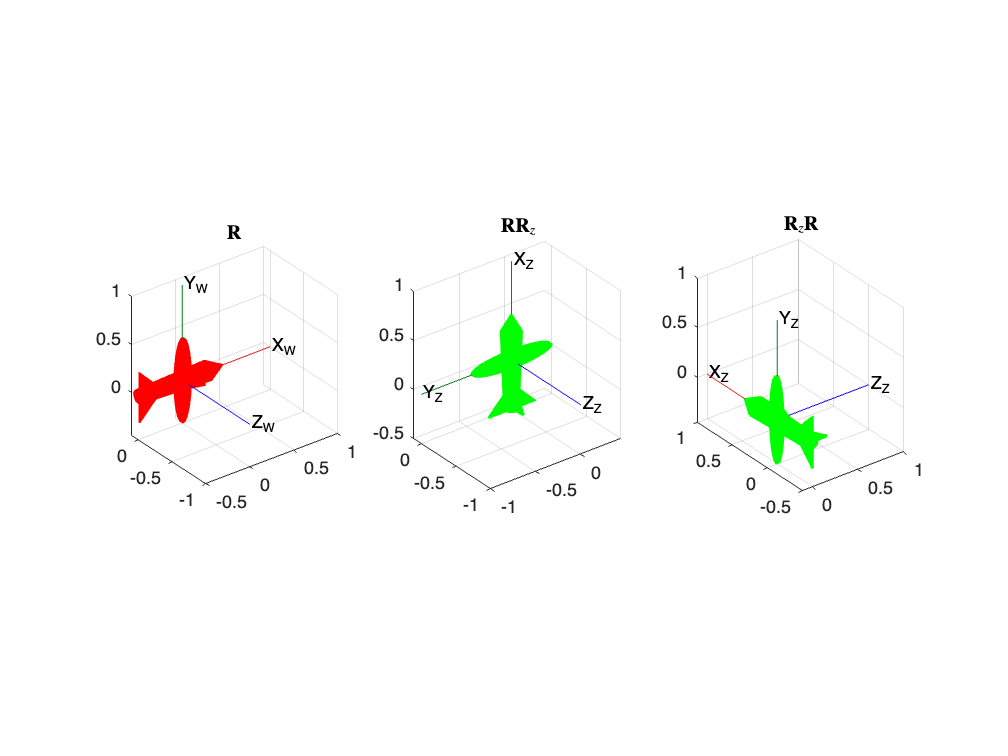

psi = 90*pi/180;

Rz = [cos(psi) -sin(psi) 0; %principle rotation about z-axis
      sin(psi) cos(psi) 0;
      0          0       1];

R = [1 0  0;
     0 0 -1;
     0 1  0];

R1 = R*Rz;
R2 = Rz*R;

figure,hold on
subplot(1,3,1),plotTransforms([0 0 0],rotm2quat(R),"MeshFilePath",'fixedwing.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title('${\bf R}$',Interpreter='latex'),grid on
subplot(1,3,2),plotTransforms([0 0 0],rotm2quat(R1),"MeshFilePath",'fixedwing.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title('${\bf R}{\bf R}_z$',Interpreter='latex'),grid on
subplot(1,3,3),plotTransforms([0 0 0],rotm2quat(R2),"MeshFilePath",'fixedwing.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title('${\bf R}_z{\bf R}$',Interpreter='latex'),grid on

## 3.3 Quaternions 

Euler angles are appealing as an introduction to understanding orientation, as they are intuitively pleasing and relatively easy to visualise. However, the potential for our rotation matrix becoming degenerate and resulting in kinematic singularities raises a red flag for many robotic applications. Additionally, the idea of describing an orientation using three sequential rotations does not follow how rigid-body robot motion will evolve in general. Instead, we would expect pure rotations about some arbitrary axis — enter the quaternion! 

The quaternion is a popular choice of encoding attitude that can completely avoid the issue of gimbal lock by rather describing the orientation as a single rotation about some defined axis that intercepts the relevant reference frame origin. At first glance, the quaternion can seem a bit daunting, but the benefits of understanding and being able to utilise it in robotics (among other fields) is worth the time investment that you may need to understand it. 

### 3.3.1 Definition

The quaternion, $\bf q$ , is a 4-element vector (also known as a 4-tuple) and is structured as


$$\begin{array}{cc}{\mathbf q} = \left[\begin{array}{cc}    q_0 \\ q_x \\ q_y \\ q_z    \\ \end{array}\right],\end{array}$$


in which$\{q_0, q_x, q_y,q_z\}$ are real numbers. In the context of describing orientation, we only consider *unit quaternions*, which gives us the unit-norm constraint of


$$\begin{array}{cc} |{\bf q}|=q_0^2+ q_x^2+ q_y^2+ q_z^2 = 1.\end{array}$$


Explicitly, the unit quaternion follows an *angle-axis* structure of 


$$\begin{array}{cc}{\mathbf q} = \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\ \sin{\frac{\alpha}{2}} \hat{\mathbf v}     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\     \sin{\frac{\alpha}{2}} v_x \\    \sin{\frac{\alpha}{2}} v_y \\    \sin{\frac{\alpha}{2}} v_z    \\ \end{array}\right],\end{array}$$


where  $\hat{\mathbf v}=[v_x ~v_y ~v_z]^T$ is the unit-length ( $|\hat{\mathbf v}|=1$ ) rotation axis, and  $\alpha \in [-\pi,\pi)$ is the rotation angle, as shown in Figure 3.4. 

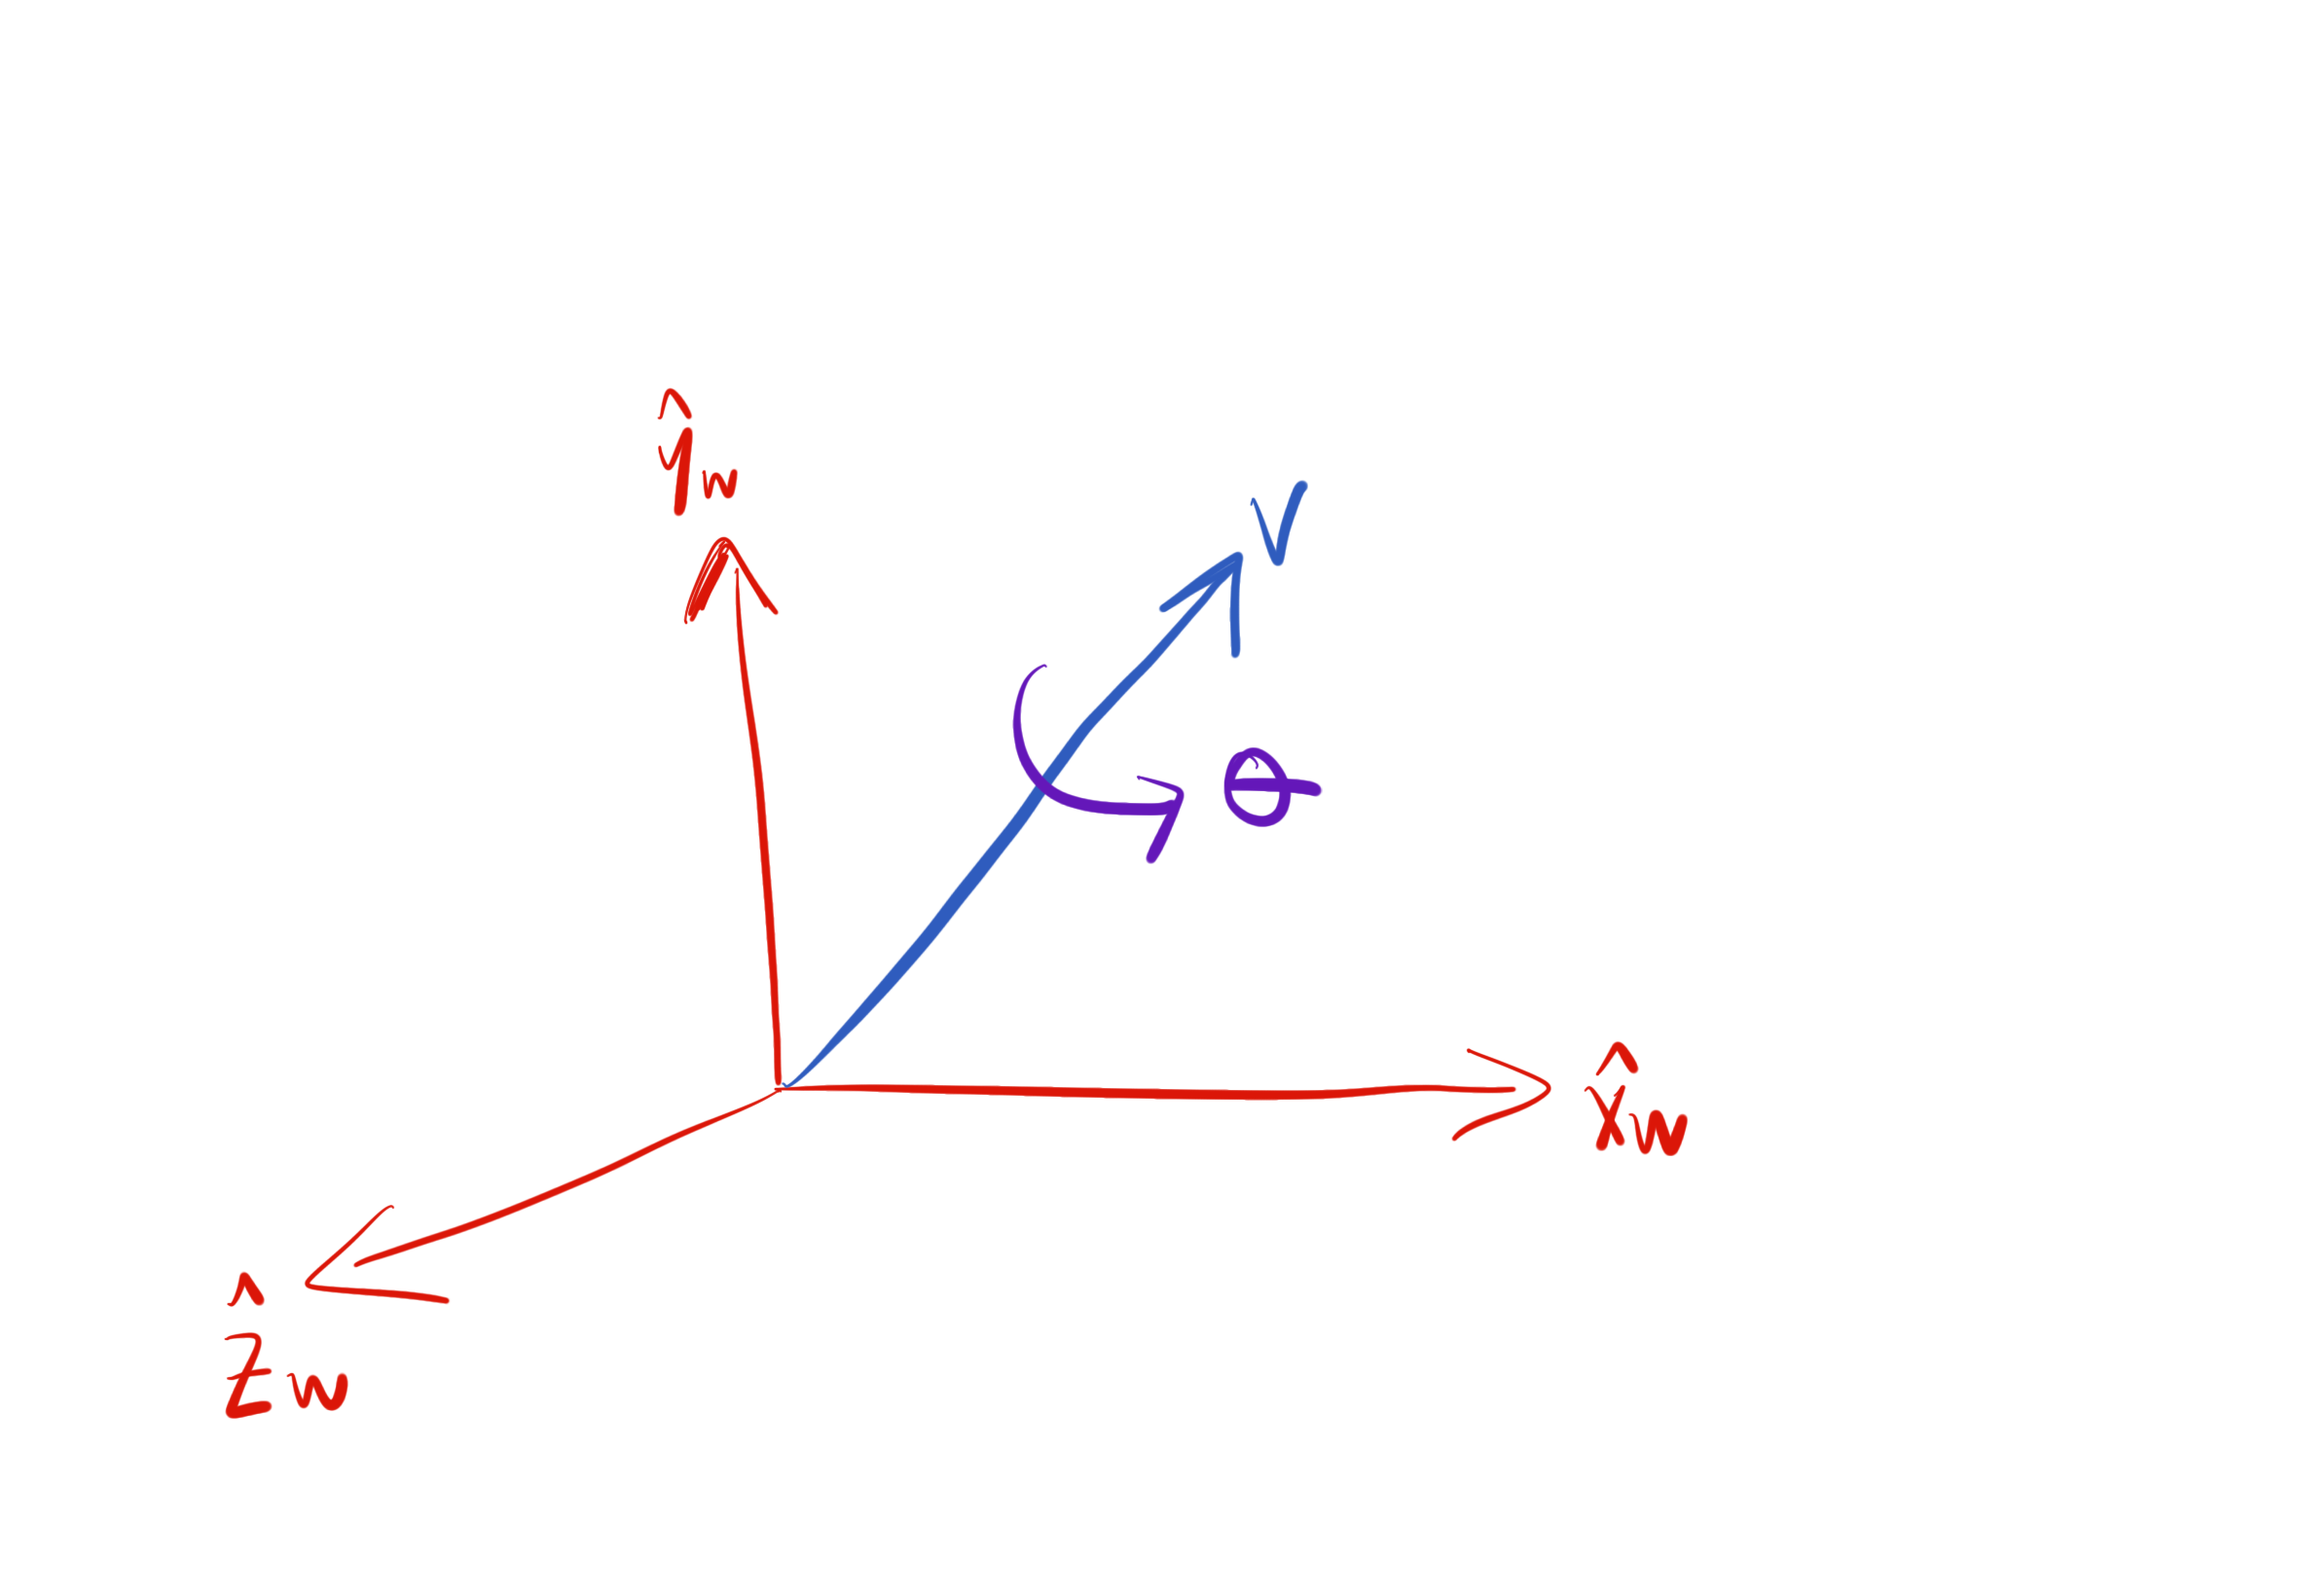

**Figure 3.4:** Visualisation of a quaternion-based rotation about vector $\bf v$ with rotational angle $\theta$ .

The code block below also shows how the quaternion axis-angle form can be used to rotate a rigid body, such as a quadcopter. The black line shows the rotation axis, $\hat{\bf v}$.

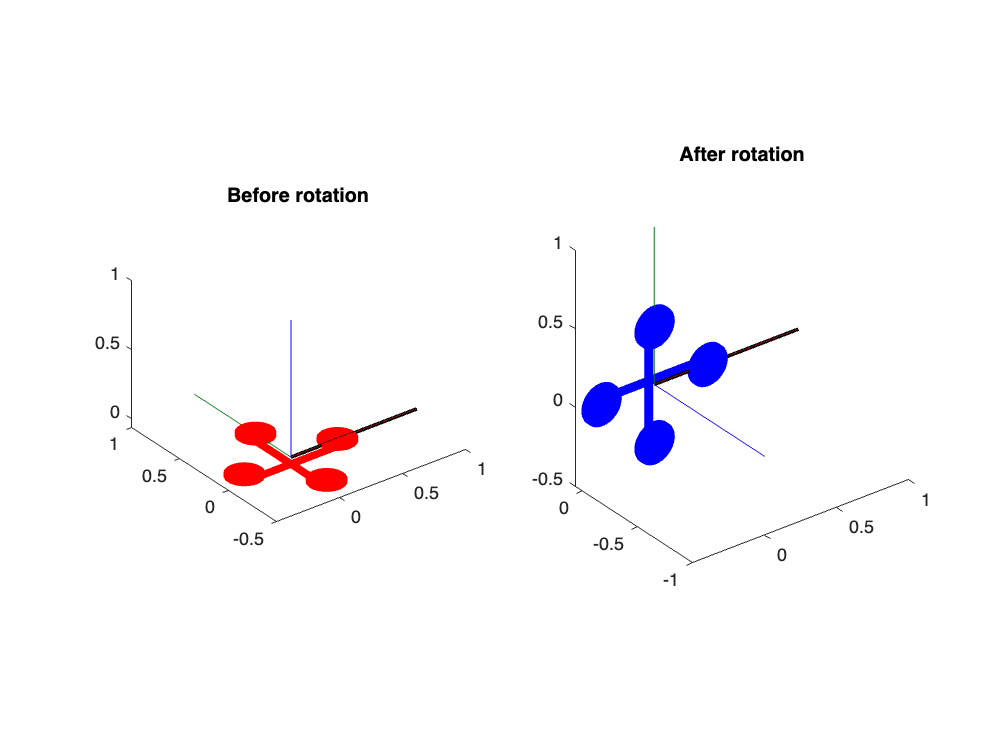

v_x = 1;
v_y = 0;
v_z = 0;
v = [v_x v_y v_z]'; 
v = v/norm(v);  %normalise v so that it always has unit length.

theta = 90*pi/180;
q = [cos(theta/2); sin(theta/2)*v];

figure 
subplot(1,2,1),hold on
plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'multirotor.stl',"MeshColor","red")
line([0 v(1)],[0,v(2)],[0,v(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('Before rotation')

subplot(1,2,2)
plotTransforms([0 0 0],q',"MeshFilePath",'multirotor.stl',"MeshColor","blue")
line([0 v(1)],[0,v(2)],[0,v(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('After rotation') 

The explicit quaternion form of


$$\begin{array}{cc}{\mathbf q} = \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\ \sin{\frac{\alpha}{2}} \hat{\mathbf v}     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\     \sin{\frac{\alpha}{2}} v_x \\    \sin{\frac{\alpha}{2}} v_y \\    \sin{\frac{\alpha}{2}} v_z    \\ \end{array}\right]
=     \left[\begin{array}{cc}    q_0 \\     q_x \\    q_y \\    q_z    \\ \end{array}\right]
\end{array}$$


 is a way of *encoding* the 3D rotation in a useful format, analogous to how rotation matrices encode attitude. We can always extract the angle-axis information from our quaternion representation using 


$$\begin{array}{cc}\alpha = 2\cos^{-1}(q_0),\end{array}$$


and 


$$\begin{array}{cc}\hat{\mathbf v} = \frac{1}{\sin{\frac{\alpha}{2}}}\left[\begin{array}{cc}    q_x \\ q_y \\ q_z    \\ \end{array}\right] =     \frac{1}{\sqrt{1-q_0^2}}    \left[\begin{array}{cc}    q_x \\ q_y \\ q_z    \\ \end{array}\right].\end{array}$$


When  $q_0=1$ , (which implies that  $\alpha=0$ ), the equation above tends to infinity, making the rotation axis become undefined. However, this is not problematic, as $\alpha=0$ corresponds to the null rotation matrix of  ${\mathbf R}={\mathbf I}$. In essence, we cannot determine the rotation vector because there is no rotation taking place. In this case, we would describe the identity (or null) quaternion as  ${\mathbf q}_{\mathbf I}=[1~ 0~ 0~ 0]^T$ . Given an angle-axis combination, we can now describe the corresponding quaternion


$$\{\alpha,\hat{\mathbf v}\}\rightarrow {\mathbf q},$$


and similarly, given a quaternion, we can recover our angle-axis pair


$${\mathbf q}\rightarrow \{\alpha,\hat{\mathbf v}\}.$$


For example, if we wanted to rotate about the $\hat{\mathbf z}_W$-axis by an angle $\alpha=\psi$, then our rotation axis would be  $\hat{\mathbf v}=\hat{\mathbf z}_W=[0 ~0~ 1]^T$ , resulting in


$$\begin{array}{cc}{^W{\mathbf q}}_Z = \left[\begin{array}{cc}          \cos{\frac{\psi}{2}} \\          0 \\          0 \\          \sin{\frac{\psi}{2}}          \\ \end{array}\right].\end{array}$$


Note that this quaternion is analogous to the principle $z$-axis rotation matrix of


$$\begin{array}{cc}{^W\mathbf R_Z} = \left[\begin{array}{cccccccc}    \cos{ \psi} & -\sin{ \psi} & 0 \\    \sin{ \psi } & \cos{ \psi } & 0 \\    0 & 0 & 1    \\ \end{array}\right].\\ \end{array}$$


The method of encoding the orientation is just different. Fortunately, there does exist a one-to-one mapping between the quaternion representation and rotation matrix, given by


$$\begin{array}{cc}{\mathbf R} = \left[\begin{array}{cccccccc}    2(q_0^2+q_x^2)-1 & 2(q_xq_y-q_0q_z) & 2(q_xq_z+q_0q_y) \\    2(q_xq_y+q_0q_z) & 2(q_0^2+q_y^2)-1 & 2(q_yq_z-q_0q_x) \\    2(q_xq_z-q_0q_y) & 2(q_yq_z+q_0q_x) & 2(q_0^2+q_z^2)-1    \\ \end{array}\right],\end{array}$$


and unsurprisingly, by substituting our result for ${^W{\mathbf q}}_Z$ into $\bf R$ above, we obtain $^W{\bf R}_Z$. 

### 3.3.2 Quaternion multiplication

While the mapping from $\bf q$ to $\bf R$ is a nice sanity check on things, we are losing one of the benefits of the quaternion, and that is its mathematical efficiency. Just as we were able to sequentially construct our body-frame orientation by using the elementary rotations when dealing with Euler angles, we can follow a similar process for the quaternion. However, we first need to cover how quaternion multiplication works. Given two quaternions, $\bf q$ and $\bf r$ , the quaternion product (or Hamilton Product), indicated using the symbol $\otimes$, is defined as


$$\begin{array}{cc}{\mathbf q} \otimes {\mathbf r} =     \left[\begin{array}{cc}    q_0r_0-q_xr_x-q_yr_y-q_zr_z \\    q_0r_x+r_0q_x+q_yr_z-r_yq_z \\    q_0r_y+r_0q_y+r_xq_z-q_xr_z \\    q_0r_z+r_0q_z+q_xr_y-r_xq_y    \\ \end{array}\right].\end{array}$$


You need not be too concerned about the finer details of this operation, just be aware that the multiplication of 4-tuples is different to what you are probably used to! Continuing with our exercise of emulating the sequential construction of our body-frame orientation as was done using ZYX Euler angles, we begin by configuring the two reference frames such that they are aligned and coincident. We then apply a rotation about  $\hat{\mathbf z}_W=[0~0~1]^T$ , with an angle of $\psi$, which gives us 


$$\begin{array}{cc}{^W{\mathbf q}}_Z = \left[\begin{array}{cc}          \cos{\frac{\psi}{2}} \\          0 \\          0 \\          \sin{\frac{\psi}{2}}          \\ \end{array}\right].\end{array}$$


We next rotate about  $\hat{\mathbf y}_Z=[0~1~0]^T$ with an angle of  $\theta$, which is encoded by the incremental quaternion of 


$$\begin{array}{cc}^Z{\mathbf q}_Y = \left[\begin{array}{cc}          \cos{\frac{\theta}{2}} \\          0 \\          \sin{\frac{\theta}{2}}\\          0           \\ \end{array}\right].\end{array}$$


Lastly, we rotate about  $\hat{\mathbf x}_Y=[1~0~0]^T$, with an angle of  $\phi$, which is described by the incremental quaternion of 


$$\begin{array}{cc}^Y{\mathbf q}_B = \left[\begin{array}{cc}          \cos{\frac{\phi}{2}} \\          \sin{\frac{\phi}{2}}\\          0 \\          0           \\ \end{array}\right].\end{array}$$


Our full description of the body-frame orientation, using the quaternion as our *encoder* follows as


$$\begin{array}{cc}{^W{\mathbf q}_B}={^W{\mathbf q}_Z} \otimes {^Z{\mathbf q}_Y} \otimes {^Y{\mathbf q}_B},\end{array}$$


and is analogous to the rotation matrix equivalent of $\begin{array}{cc}{^W {\mathbf R}_B} = {^W {\mathbf R}_Z}{^Z {\mathbf R}_Y}{^Y {\mathbf R}_B}.\\ \end{array}$ The code block below shows how to perform quaternion multiplication in `MATLAB`.

phi = 90*pi/180;
the = 30*pi/180;
psi = 0*pi/180;

q_z2w = [cos(psi/2) 0 0 sin(psi/2)];
q_y2z = [cos(the/2) 0 sin(the/2) 0];
q_b2y = [cos(phi/2) sin(phi/2) 0 0];

q_b2w = quatmultiply( quatmultiply(q_z2w,q_y2z), q_b2y )

q_b2w =     0.6830    0.6830    0.1830   -0.1830


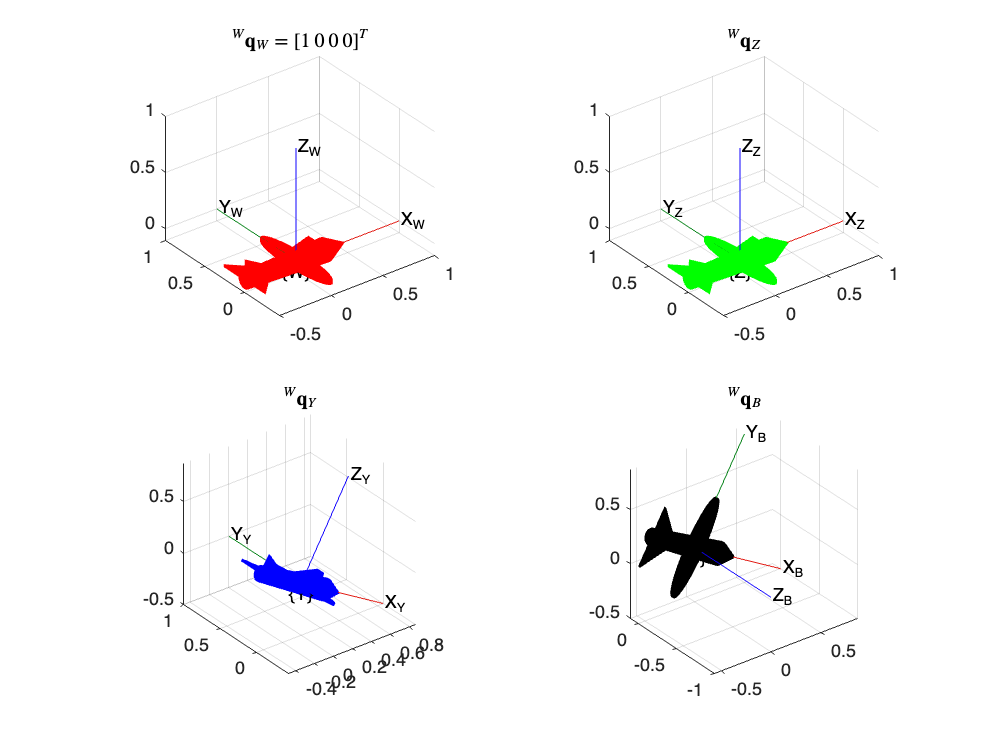


figure,hold on
subplot(2,2,1),plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'fixedwing.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title('$^W{\bf q}_W=[1~0~0~0]^T$',Interpreter='latex'),grid on
subplot(2,2,2),plotTransforms([0 0 0],q_z2w,"MeshFilePath",'fixedwing.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title('$^W{\bf q}_Z$',Interpreter='latex'),grid on
subplot(2,2,3),plotTransforms([0 0 0],quatmultiply(q_z2w,q_y2z),"MeshFilePath",'fixedwing.stl',"MeshColor","blue","FrameAxisLabels","on","FrameLabel","Y")
axis equal, title('$^W{\bf q}_Y$',Interpreter='latex'),grid on
subplot(2,2,4),plotTransforms([0 0 0],quatmultiply( quatmultiply(q_z2w,q_y2z),q_b2y),"MeshFilePath",'fixedwing.stl',"MeshColor","black","FrameAxisLabels","on","FrameLabel","B")
axis equal, title('$^W{\bf q}_B$',Interpreter='latex'),grid on

As with the Euler angles, we have followed the ordering of $\{W\} \rightarrow \{Z\} \rightarrow \{Y\} \rightarrow \{B\}.$ Quaternions can also be thought of as being intrinsic or extrinsic — when post-multiplying by a quaternion, we can imagine the rotation vector being described in the current frame (as above), whereas when pre-multiply the vector is described in $\{W\}$.

Note that in this particular case, our quaternions are still parameterised by the Euler angles. This is not how we will usually make use of quaternions; rather, this is a demonstration of how quaternion rotation works, and its relationship with Euler angles and rotation matrices.

It is worth highlighting the numerical efficiency of the quaternion — while multiplying two rotation matrices requires 27 multiplications and 18 additions, quaternion multiplication only requires 16 multiplications and 12 additions. This may seem insignificant, but in certain applications where processing power is limited, or a large number of coordinate mappings are required (e.g. in the video game instustry) this FLOP saving is envaluable! 

As with the rotation matrix, the quaternion has an inverse, defined as


$$\begin{array}{cc}{\mathbf q}^{-1} = \left[\begin{array}{cc}    q_0 \\    -q_x \\    -q_y \\    -q_z    \\ \end{array}\right].\end{array}$$


We can think of this inverse in one of two ways: either 

- (i) the rotation vector changes direction and points in the opposite direction, or 

- (ii) the rotation angle changes direction. 

In either case, the quaternion inverse can be thought of as "undoing" a rotation. 

If we rotated our robot such that our quaternion was  ${\mathbf a}=[a_0 ~a_x ~a_y ~a_z]^T$ , followed by multiplication of the inverse,  ${\mathbf a}^{-1}=[a_0 ~-a_x ~-a_y ~-a_z]^T$ , we would return to our identity quaternion,  ${\mathbf a}^{-1}\otimes {\mathbf a}=[1 ~0 ~0 ~0]^T$ . 

alpha = 45*pi/180;
vx = [1 1 1]; 
vx = vx/norm(vx);

q = [cos(alpha/2) sin(alpha/2)*vx];

q_I = quatmultiply( quatinv(q),q )

q_I =      1     0     0     0


### 3.3.3 Rotating a frame

The sequential process of building a quaternion using the principal axis rotations is useful for demonstrating the parallel between rotation matrices and quaternions, but there is actually no need to ever use Euler angles when incorporating quaternions. As previously mentioned, the orientation can be defined using a rotation vector,  $\hat{\mathbf v}$ , and rotation angle $\alpha$ about  $\hat{\mathbf v}$ . In other words, we can define a mapping between two reference frames by either rotating about a single vector with a specific rotation angle (quaternion), or equivalently performing three sequential rotations about the intrinsic axes (Euler-parameterised rotation matrix). The quaternion approach is generally quite appealing for robotics, as it matches the "natural" rotational behaviour. That is, incremental rotations will occur as a single motion, not three discrete motions. Later chapters will also demonstrate that quaternions are highly beneficial when confronting the rigid-body robotic control problem, whereas Euler angles can become unreliable for large angular errors. 

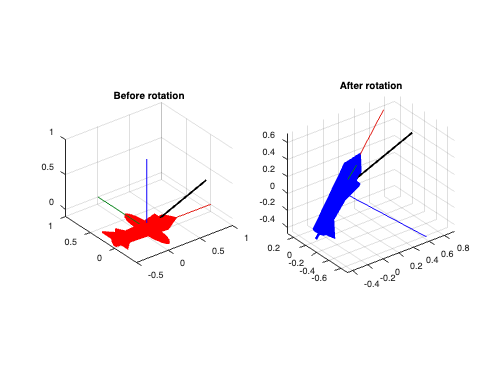

v_x = 1;
v_y = 0;
v_z = 0.4;
v = [v_x v_y v_z]'; 
v = v/norm(v);  %normalise v so that it always has unit length.

theta = 130*pi/180;
q = [cos(theta/2); sin(theta/2)*v];

figure 
subplot(1,2,1),hold on
plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'fixedwing.stl',"MeshColor","red")
line([0 v(1)],[0,v(2)],[0,v(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('Before rotation'),grid on

subplot(1,2,2)
plotTransforms([0 0 0],q',"MeshFilePath",'fixedwing.stl',"MeshColor","blue")
line([0 v(1)],[0,v(2)],[0,v(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('After rotation'),grid on

### 3.3.4 Double cover

There is one minor caveat that should be made clear when using quaternions. We are operating in a 3D Euclidean space, but the quaternion is a 4-element vector. So why does the quaternion have 4 parameters to specify a 3D orientation? The simple answer is that a single quaternion does not uniquely define an orientation. That is, the orientation derived using a rotation about some axis is equivalent to a negative rotation about that same axis after it has been inverted. This results in a **double cover** phenomenon where  $\mathbf q$ and  $-{\mathbf q}$ represent the same rotation. 

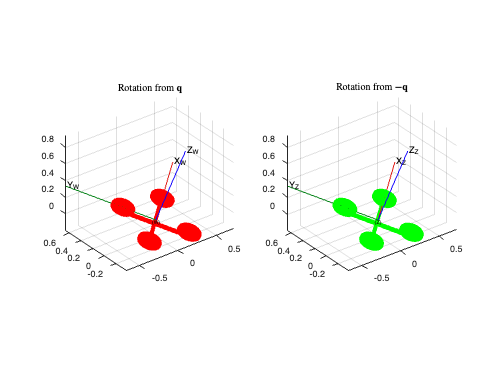

q0 = 1;
qx = 0.2;
qy = 0;
qz = 0.4;
q = [q0 qx qy qz];
q = q/norm(q);

figure,hold on
subplot(1,2,1),plotTransforms([0 0 0],q,"MeshFilePath",'multirotor.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title(['Rotation from ','$\bf q$'],Interpreter='latex'),grid on
subplot(1,2,2),plotTransforms([0 0 0],-q,"MeshFilePath",'multirotor.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title(['Rotation from ','$\bf -q$'],Interpreter='latex'),grid on

#### **Example: Double cover**

You rotate an arbitrary reference frame about a specified rotation vector,  $\hat{\mathbf v}$, by some angle  $\phi$, giving us the quaternion  

${\mathbf q}_1=[\cos(\phi/2) \hat{\mathbf v}^T \sin(\phi/2)]^T$ . 

If we had decided to instead rotate about the same rotation vector but in the opposite direction with a rotation angle of  $\phi-2\pi$ , our quaternion would follow as 


$${\mathbf q}_2=[\cos(\frac{\phi-2\pi}{2}) \hat{\mathbf v}^T \sin(\frac{\phi-2\pi}{2})]^T=[\cos(\phi/2-\pi) \hat{\mathbf v}^T \sin(\phi/2-\pi)]^T.$$


Noting the periodic nature of the $\cos$ and $\sin$ functions, we can make use of  $\sin({x-\pi})=-\sin{x}$ and  $\cos({x-\pi})=-\cos{x}$ to reduce  ${\mathbf q}_2$ to  ${\mathbf q}_2=[-\cos(\phi/2) \hat{\mathbf v}^T -\sin(\phi/2)]^T=-{\mathbf q}_1$.

As a result of this double covering, every orientation will map to two quaternions; one that describes the minimum angle rotation, and the other describing the maximum angle rotation. The only exception is the special case where the rotation angle is $180^\circ$ , making both rotations equivalent in terms of angular distance. This disparity between a minimum and maximum angle rotation becomes important when our robot is trying to follow a path, as we commonly desire minimal angular changes that result in smaller time and energy requirements (the minimum angle rotation).

### 3.3.5 Rotating vectors

We have already shown that quaternions can be used to (i) represent orientation and (ii) rotate frames. Analogous to rotation matrices, quaternions also posess the third property of being able to map vectors between frames. We will not explore this in detail in this course, but the following formulation can be used to rotate a vector between two frames:


$$...$$


## 3.4 Exponential coordinates

### 3.4.1 Definition

Analogous to quaternions, exponential coordinates parameterise an orientation in terms of a rotation axis, represented by a unit vector $\hat{\bf v}$, and an angle of rotation $\alpha$; the vector $\alpha\hat{\bf v}\in \mathbb{R}^3$ then serves as the three-parameter exponential coordinate representation of the rotation. Writing $\hat{\bf v}$ and $\alpha$ individually is known as the axis-angle representation of a rotation.

Exponential coordinates can be used to describe orientations and also map vectors between frames. However, before we can show this result, we need to introduce the skew-symmetric matrix.

#### **Definition:** Skew-symmetric matrix

A **skew-symmetric matrix** is a square matrix whose transpose equals its negative: ${\mathbf S}^T=-{\mathbf S}$.

By this definition, the diagonal elements of  ${\mathbf S}$ must all equal zero in order to satisfy  ${\mathbf S}^T=-{\mathbf S}$ . Skew-symmetric matrices are useful in reposing a vector cross product operation as a matrix-vector multiplication, as we will show in the following section. Given an arbitrary vector  ${\bf v}=[v_x ~v_y~v_z]^T$ , the corresponding skew-symmetric matrix operator is


$$\begin{array}{cc}\lfloor {\bf v} \rfloor = \left[\begin{array}{cccccccc}    0 & -v_z & v_y \\    v_z & 0 & -v_x \\    -v_y & v_x & 0    \\ \end{array}\right],\end{array}$$


which shows the symmetry across the diagonal, albeit with a sign change. 

Note that if we wanted to evaluate a cross product operation such as  ${\bf v} \times {\mathbf p}$ , we could repose it as  ${\bf v} \times {\mathbf p}=\lfloor {\bf v} \rfloor{\mathbf p}$ , which is a vector multiplying into a matrix (not a cross product of two vectors). However, the result would remain the same. 

### 3.4.2 Exponential coordinates of rotations

It can be shown that a rotation matrix, parameterised using the axis-angle representation, is given by the matrix exponential mapping


$${\bf R}=\mathrm{e}^{\lfloor \alpha\hat{\bf v} \rfloor}=\mathrm{e}^{\lfloor \hat{\bf v} \rfloor\alpha}.$$


Note that the matrix exponential differs to the standard single-element matrix exponential and in general is described by


$$\mathrm{e}^{\bf A}=I+t{\bf A}+\frac{t^2}{2!}{\bf A}^2+\frac{t^3}{3!}{\bf A}^3+\dots ,$$


where ${\bf A}\in \mathbb{R}^{n\times n$ is constant. For the special case when ${\bf A}={\lfloor \hat{\bf v} \rfloor\alpha}$, the equation above can be reduced without loss of generality as


$${\bf R}=\mathrm{e}^{\lfloor \hat{\bf v} \rfloor\alpha}=I+\sin\alpha\lfloor \hat{\bf v} \rfloor +\left(1-\cos\alpha\right)\lfloor \hat{\bf v} \rfloor^2.$$


The equation above is known as **Rodrigues' formula **for rotations and is a convenient means of building a rotation matrix from exponential coordinates without having to evaluate the matrix exponential.

Writing out the above equation explicitly yields


$${\bf R}= \left[\begin{array}{cccccccc}    \mathrm{c}_\alpha+\hat{v}_1^2(1-\mathrm{c_\alpha}) & \hat{v}_1\hat{v}_2(1-\mathrm{c}_\alpha)-\hat{v}_3\mathrm{s}_\alpha & \hat{v}_1\hat{v}_3(1-\mathrm{c}_\alpha)+\hat{v}_2\mathrm{s}_\alpha \\    \hat{v}_1\hat{v}_2(1-\mathrm{c}_\alpha)+\hat{v}_3\mathrm{s}_\alpha & \mathrm{c}_\alpha+\hat{v}_2^2(1-\mathrm{c_\alpha}) & \hat{v}_2\hat{v}_3(1-\mathrm{c}_\alpha)-\hat{v}_1\mathrm{s}_\alpha  \\    \hat{v}_1\hat{v}_3(1-\mathrm{c}_\alpha)-\hat{v}_2\mathrm{s}_\alpha & \hat{v}_2\hat{v}_3(1-\mathrm{c}_\alpha)+\hat{v}_1\mathrm{s}_\alpha & \mathrm{c}_\alpha+\hat{v}_3^2(1-\mathrm{c_\alpha})    \\ \end{array}\right],$$


where $\hat{\bf v}=[\hat{v}_1~\hat{v}_2~\hat{v}_3]^T$, using the shorthand notation of $\mathrm{s}_\alpha=\sin{\alpha}$ and $\mathrm{c}_\alpha=\cos{\alpha}$.

#### Example: Using Rodrigues' formula

Determine the pose of $\{B\}$ with respect to $\{W\}$ when a frame initial aligned with $\{W\}$ experiences a rotation about ${^W\hat{\bf v}}=[0~0.866~0.5]^T$ with an angle of $\alpha=30^\circ=0.524$ rad.

Using Rodrigues' formula, we obtain


$$\begin{array}{ll}
{^W{\bf R}_B}
&=\mathrm{e}^{\lfloor ^W\hat{\bf v} \rfloor\alpha},\\
&=I+\sin\alpha\lfloor ^W\hat{\bf v} \rfloor +\left(1-\cos\alpha\right)\lfloor ^W\hat{\bf v} \rfloor^2,\\
&=I+0.5\left[\begin{array}{cccccccc}    0 & -0.5 & 0.866 \\    0.5 & 0 & 0 \\    -0.866 & 0 & 0    \\ \end{array}\right]+0.134\left[\begin{array}{cccccccc}    0 & -0.5 & 0.866 \\    0.5 & 0 & 0 \\    -0.866 & 0 & 0    \\ \end{array}\right]^2,\\
&= \left[\begin{array}{cccccccc}    0.866 & -0.250 & 0.433 \\    0.250 & 0.967 & 0.058 \\    -0.433 & 0.058 & 0.899    \\ \end{array}\right].
\end{array}$$


v = [0 0.866 0.5]';
alpha = 30*pi/180;

S = [0 -v(3) v(2);
     v(3) 0 -v(1);
     -v(2) v(1) 0];

R = expm(S*alpha)

R =     0.8660   -0.2500    0.4330
    0.2500    0.9665    0.0580
   -0.4330    0.0580    0.8995


R_ = eye(3)+sin(alpha)*S+( 1-cos(alpha) )*S^2

R_ =     0.8660   -0.2500    0.4330
    0.2500    0.9665    0.0580
   -0.4330    0.0580    0.8995


### 3.4.3 Matrix logarithms of rotations

We can recover the exponential coordinates, $\alpha\hat{\bf v}$ from a rotation matrix ${\bf R}$ using a **matrix logarithm **operation, which is the inverse of the matrix exponential. Specifically, if the rotation matrix is given by


$${\bf R}=\mathrm{e}^{\lfloor \alpha\hat{\bf v} \rfloor}=\mathrm{e}^{\lfloor \hat{\bf v} \rfloor\alpha},$$


then the matrix logarithm of the rotation matrix yields


$${\lfloor \hat{\bf v} \rfloor\alpha} = \log{\bf R}.$$


Based on this, we can think of the matrix exponential as in *integration operator *for the exponential coordinates, and the matrix logarithm as a *differentiation operator*.

#### Example: Matrix logarithm

Using MATLAB, determine the rotation matrix corresponding to $\hat{\bf v}=[0~0.866~0.6]^T$ and $\alpha=30^\circ$, and show that the exponential coordinates can be recovered using the matrix logarithm.

v = [0 0.866 0.5]';
alpha = 30*pi/180;

S = [0 -v(3) v(2);
     v(3) 0 -v(1);
     -v(2) v(1) 0];

R = expm(S*alpha);

S_ = logm(R);
va = [-S_(2,3) S_(1,3) -S_(1,2)]';
alpha_ = norm( va )

alpha_ = 0.5236

v_ = va/alpha

v_ =     0.0000
    0.8660
    0.5000


Instead of having to use the matrix logarithm, an algorithm exists that can determine the exponential coordinates. The rotation angle can be determined from the rotation matrix using


$$\alpha=\cos^{-1}\left(\frac{1}{2}\left(\mathrm{tr}{\bf R}-1\right)\right),$$


where $\mathrm{tr}{\bf R}$ corresponds to the trace of matrix ${\bf R}$, namely, summing the diagonal entries of ${\bf R}$:

$\mathrm{tr}{\bf R}=r_{11}+r_{22}+r_{33}$.

For $\alpha\neq \pi$, the rotation vector (in skew-symmetric form) is determined by


$$\lfloor \hat{\bf v} \rfloor = \frac{1}{2\sin{\alpha}}\left({\bf R}-{\bf R}^T\right).$$


For the special case of $\alpha=\pi$, the rotation vector is one of the following solutions, which would need to be verified using ${\bf R}=\mathrm{e}^{\lfloor \hat{\bf v} \rfloor\alpha}$:


$$\hat{\bf v}=\frac{1}{\sqrt{2(1+r_{33})}}\left[\begin{array}{cc}    r_{13} \\   r_{23} \\    1+r_{33}    \\ \end{array}\right], \qquad \hat{\bf v}=\frac{1}{\sqrt{2(1+r_{22})}}\left[\begin{array}{cc}    r_{12} \\   1+r_{22} \\    r_{32}    \\ \end{array}\right]
, \qquad \hat{\bf v}=\frac{1}{\sqrt{2(1+r_{11})}}\left[\begin{array}{cc}    1+r_{11} \\   r_{21} \\    r_{31}    \\ \end{array}\right].$$


### 3.4.4 The cross product

Recall that the cross product of two unitary vectors is described by


$$\hat{\bf a}\times \hat{\bf b}=\sin{\theta} \hat{\bf c},$$


where $\theta$ describes the angle between vectors $\hat{\bf a}$ and $\hat{\bf b}$, and $\hat{\bf c}$ defines the vector perpendicular to $\hat{\bf a}$ and $\hat{\bf b}$. Based on this description, if we were to rotate $\hat{\bf a}$ about $\hat{\bf c}$ with a rotation of $\theta$ units, we would obtain $\hat{\bf b}$, namely


$$\begin{array}{ll}
\hat{\bf b}
&={\bf R}\hat{\bf a},\\
&={\bf e}^{\lfloor\theta\hat{\bf c}\rfloor}\hat{\bf a}.\\
\end{array}$$


As such, $\theta\hat{\bf c}$ can be thought of as exponential coordinates describing the mapping from $\hat{\bf a}$ and $\hat{\bf b}$. This relationship is useful when deadling with control design (e.g. thrust vectoring control) and state estimation (comparing vector directions) — both of which will be explored later in this course. Note that when $\theta$ is sufficiently small, the exponential coordinates can be approximatd by $\hat{\bf a}\times \hat{\bf b}=\sin{\theta} \hat{\bf n}\approx {\theta} \hat{\bf n}$.

#### Example: Cross product and rotation matrix

a = [1 2 3]';
a = a/norm(a);
b = [-1 1 3]';
b = b/norm(b)

b =    -0.3015
    0.3015
    0.9045



c = cross(a,b);
theta = asin(norm(c));
n = c/sin(theta);

phi = theta*n;
S = [0 -phi(3) phi(2);
    phi(3) 0 -phi(1);
    -phi(2) phi(1) 0];

R = expm(S);
b_ = R*a

b_ =    -0.3015
    0.3015
    0.9045


## 3.5 Angular velocity

Angular velocity will dictate how our orientation changes over time, so we are therefore interested in how the two are related when dealing with multiple reference frames. This is important when mathematically modelling systems (for example when designing simulation environments) and also when angular rate information is available from a sensor (for example a gyroscope) and we want to estimate orientation from it. 

In the case of planar rotations (resulting in rotations about a fixed principle axis) the relationship is trivial, but we require more scrutiny for the generalised spatial case when up to three degrees of rotation freedom are at work.

### 3.5.1 Rotation matrix derivative

To understand the relationship between angular velocity and orientation, we need to develop a better understanding of reference frame motion as they rotate. Consider the motion of a point fixed to the end of ${^W\hat{\bf x}_B$. Recall that this describes the $x$-axis of the body frame with respect to the world frame, obtained by


$$\begin{array}{ll}
{^W\hat{\bf x}_B
&={^W{\bf R}_B\hat{\bf x}_B,\\
&={^W{\bf R}_B\left[\begin{array}{cccccccc}    1 \\    0 \\   0    \\ \end{array}\right].\\
\end{array}$$


Given the orthogonality property of ${^W{\bf R}_B$, ${^W\hat{\bf x}_B$ will always have unit length. This means that during rotation, only the direction of ${^W\hat{\bf x}_B$ will change. Given that the angular velocity of the body frame is described in the world frame as ${^W{\bf \omega}}$, we can determine the rate of change of ${^W\hat{\bf x}_B$ based on elementary mechanics, namely

${^W\dot{\hat{\bf x}}_B}={^W{\bf\omega}}\times {^W{\hat{\bf x}}_B}$.

We can repeat this process for the other two axes of $\{B\}$without loss of generality, which yields 

${^W\dot{\hat{\bf y}}_B}={^W{\bf\omega}}\times {^W{\hat{\bf y}}_B}$.

${^W\dot{\hat{\bf z}}_B}={^W{\bf\omega}}\times {^W{\hat{\bf z}}_B}$.

Recalling that


$$\begin{array}{cc}^W{\mathbf R}_B =     \left[\begin{array}{cccc}    ^W{\hat{\mathbf x}}_B & ^W{\hat{\mathbf y}}_B & ^W{\hat{\mathbf z}}_B    \\ \end{array}\right],\ \end{array}$$


the derivative of the rotation matrix follows as


$$\begin{array}{ll}^W\dot{\mathbf R}_B 
&=     \left[\begin{array}{cccc}    ^W\dot{\hat{\mathbf x}}_B & ^W\dot{\hat{\mathbf y}}_B & ^W\dot{\hat{\mathbf z}}_B    
\end{array}\right],\\
&=     \left[\begin{array}{cccc}    {^W{\bf\omega}}\times {^W\hat{\bf x}_B} & {^W\bf\omega}\times {^W\hat{\bf y}_B} & {^W{\bf\omega}}\times {^W\hat{\bf z}_B}\\
\end{array}\right].\\


\end{array}$$


Making use of our skew-symmetric form for the cross product, namely


$$\begin{array}{cc}
{{\bf \omega} \times {\bf r} = 
\lfloor {\mathbf\omega} \rfloor {\bf r}, \end{array}$$


we can express the rotation matrix derivative as


$$\begin{array}{ll}^W\dot{\mathbf R}_B 
&=     \left[\begin{array}{cccc}    {^W{\bf\omega}}\times {^W\hat{\bf x}_B} & {^W\bf\omega}\times {^W\hat{\bf y}_B} & {^W{\bf\omega}}\times {^W\hat{\bf z}_B}\\
\end{array}\right],\\
& = \lfloor {^W\mathbf\omega} \rfloor \left[\begin{array}{cccc}     {^W\hat{\bf x}_B} &  {^W\hat{\bf y}_B} &  {^W\hat{\bf z}_B}\\
\end{array}\right],\\
& = \lfloor {^W\mathbf\omega} \rfloor  {^W{\mathbf R}_B}.

\end{array}$$


This result is quite interesting as it suggests that the rate of change of our orientation encoder will be a function of both the angular velocity vector and current orientation. It can easily be shown that for any ${\bf R}\in$ SO(3) and $\bf \omega\in \mathbb{R}^3$,


$$\begin{array}{cc}\lfloor {\mathbf R}{\mathbf\omega} \rfloor = {\mathbf R}\lfloor {\mathbf\omega} \rfloor {\mathbf R}^T. \end{array}$$


Recall that we can relate the angular velocity between different frames using


$$\begin{array}{cc}{^W\mathbf\omega} = {^W{\mathbf R}_B} {^B\mathbf\omega}, \end{array}$$


and this, along with the result above of $\begin{array}{cc}\lfloor {\mathbf R}{\mathbf\omega} \rfloor = {\mathbf R}\lfloor {\mathbf\omega} \rfloor {\mathbf R}^T \end{array}$ can be used to determine the rotation matrix derivative as


$$\begin{array}{ll}^W\dot{\mathbf R}_B 

& = \lfloor {^W\mathbf\omega} \rfloor  {^W{\mathbf R}_B},\\
& = \lfloor {{^W{\mathbf R}_B}^B\mathbf\omega} \rfloor  {^W{\mathbf R}_B},\\
& = {^W{\mathbf R}_B}\lfloor {^B\mathbf\omega} \rfloor  {^W{\mathbf R}^T_B}{^W{\mathbf R}_B},\\
& = {^W{\mathbf R}_B}\lfloor {^B\mathbf\omega} \rfloor  .
\end{array}$$


Note the similarity when determining $\begin{array}{ll}^W\dot{\mathbf R}_B 



\end{array}$ as a function of $^W{\bf \omega}$ and $^B{\bf \omega}$. 

### 3.5.2 Quaternion derivative

The relationship between angular velocity and the quaternion follows a similar pattern to that of the rotation matrix counterpart. The full derivation will be spared here for sake of time. Analogous to the result of $\begin{array}{ll}^W\dot{\mathbf R}_B 

& = \lfloor {^W\mathbf\omega} \rfloor  {^W{\mathbf R}_B}

\end{array}$, the quaternion derivative can be written as 


$$\begin{array}{cc}{^W\dot{\mathbf q}_B} = \frac{1}{2}{^W\mathbf\Omega}\otimes{^W{\mathbf q}_B},\end{array}$$


where 


$$\begin{array}{ll}
{^W\mathbf\Omega}
&=\left[\begin{array}{cccccccc}    0 \\    ^W{\bf\omega}    \\ \end{array}\right]\\
\end{array}$$


is a "pure" quaternion formed from the angular velocity vector in frame $\{W\}$. Using appropriate identities, the quaternion derivative can be written as 


$$\begin{array}{cc}{^W\dot{\mathbf q}_B} = \frac{1}{2}{^W{\mathbf q}_B}\otimes{^B\mathbf\Omega},\end{array}$$


which follows a similar structure but now using the angular velocity in frame $\{B\}$. 

## 3.6 Obtaining orientation from angular velocity

If the angular velocity is known exactly, we can use this information to determine the corresponding orientation at a given time using integration. We must, however, take into account the particular reference frame mapping, such as from $\{B\}$ to $\{W\}$, before performing the integration operation — otherwise the resulting "orientation" described in $\{B\}$ is meaningless in general.

### 3.6.1 Rotation matrix formulation

The incremental orientation can be determined in rotation matrix form using exponential coordinates. Recall that 


$${\bf R}=\mathrm{e}^{\lfloor \alpha\hat{\bf v} \rfloor}=\mathrm{e}^{\lfloor \hat{\bf v} \rfloor\alpha},$$


where $\alpha\hat{\bf v}$ are the exponential coordinates describing the generalised 3D rotation. Given an angular velocity vector of ${^B{\bf \omega}}$, expressed in $\{B\}$, and a sample time of $\Delta t$, we can determine the incremental exponential coordinates corresponding to rotating about vector ${^B{\bf \omega}}$ for $\Delta t$ units of time (usually seconds) using 


$${^B{\bf \theta}={^B{\bf \omega}}\Delta t.$$


The incremental rotation angle and normalised rotation vector follow respectively as 


$$\Delta \alpha=|{^B{\bf \omega}}|\Delta t,$$



$${^B\hat{\bf \omega}}=\frac{^B{\bf \omega}}{|{^B{\bf \omega}}|}.$$


The corresponding incremental rotation matrix is given by


$$\begin{array}{ll}
\Delta{\bf R}
&=\mathrm{e}^{\lfloor {^B{\bf \theta}} \rfloor},\\
&=\mathrm{e}^{\lfloor {^B{\bf \omega}}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\alpha\lfloor ^B\hat{\bf \omega} \rfloor +\left(1-\cos\Delta\alpha\right)\lfloor ^B\hat{\bf \omega} \rfloor^2,\\
&={\bf I}+\sin(|{^B{\bf \omega}}|\Delta t)\lfloor ^B\hat{\bf \omega} \rfloor +\left(1-\cos(|{^B{\bf \omega}}|\Delta t)\right)\lfloor ^B\hat{\bf \omega} \rfloor^2.
\end{array}
$$


If our orientation is originally described as $^W{\bf R}_{\{0\}}$ prior to experiencing the angular velocity, we can then determine our updated orientation, ${^W{\bf R}_{\{1\}}}$, by post-multiplying $^W{\bf R}_{\{0\}}$ by the incremental rotation matrix, namely


$${^W{\bf R}_{\{1\}}}={^W{\bf R}_{\{0\}}}{^{\{0\}}{\bf R}_{\{1\}},$$
 

where $\Delta{\bf R}={^{\{0\}}{\bf R}_{\{1\}}
$ is the incremental orientation as a result of the body-frame angular velocity. This process can be repeated any number of times, assuming one is able to capture each incremental rotation matrix that corresponds to the angular velocity that was experienced for the given time frame. This is expressed as


$${^W{\bf R}_{\{n\}}}={^W{\bf R}_{\{0\}}}{^{\{0\}}{\bf R}_{\{1\}} \dots {^{\{n-1\}}{\bf R}_{\{n\}}.$$
 

### 3.6.2 Quaternion formulation

Recall that the quaternion encodes the exponential coordinates. Given our previously defined incremental axis-angle representation of


$$\Delta \alpha=|{^B{\bf \omega}}|\Delta t,$$
        
$${^B\hat{\bf \omega}}=\frac{^B{\bf \omega}}{|{^B{\bf \omega}}|},$$


we can determine the corresponding incremental quaternion as


$$\begin{array}{cc}\Delta{\mathbf q} = \left[\begin{array}{cc}    \cos{\frac{\Delta\alpha}{2}} \\ \sin{\frac{\Delta\alpha}{2}} {^B\hat{\mathbf \omega}}     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \\     \sin{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \hat{\omega}_x \\    \sin{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \hat{\omega}_y \\    \sin{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \hat{\omega}_z    \\ \end{array}\right].\end{array}$$


If our orientation is originally described by $^W{\bf q}_{\{0\}}$ prior to experiencing the angular velocity, we can then determine our updated orientation, ${^W{\bf q}_{\{1\}}}$, by post-multiplying $^W{\bf q}_{\{0\}}$ by the incremental quaternion, namely


$${^W{\bf q}_{\{1\}}}={^W{\bf q}_{\{0\}}}\otimes{^{\{0\}}{\bf q}_{\{1\}},$$
 

where $\Delta{\bf q}={^{\{0\}}{\bf q}_{\{1\}}
$ is the incremental orientation as a result of the body-frame angular velocity. This process can be repeated any number of times, assuming one is able to capture each incremental rotation matrix that corresponds to the angular velocity that was experienced for the given time frame. This is expressed as


$${^W{\bf q}_{\{n\}}}={^W{\bf q}_{\{0\}}}\otimes{^{\{0\}}{\bf q}_{\{1\}}\otimes \dots \otimes{^{\{n-1\}}{\bf q}_{\{n\}}.$$
 

## 3.7 Body-frame orientation error

Correcting the orientation of a generic platform follows a similar thinking as that of the position error, albeit with some additional intricacies. We will consider two approaches to generating a description of the body-frame orientation error:

- Rotation matrices

- Quaternions

Euler angles are appealing when dealing with planar robots, as only a single angle is required to describe the orientation of a rigid-body system, and we end up inadvertently avoiding all the nastiness that goes along with the Euler angle formulation (sequential rotations and potential for singularity). In the case of the mobile robot for example, we can define an orientation error, described in frame $\{W\}$ , using $e_\psi=\psi^\ast-\psi$ . The angle and corresponding angular error here is effectively one of our Euler angles, with the other two Euler angles set to zero. However, when dealing with robotic platforms that can move outside of a fixed plane (e.g. a quadcopter), simply taking the difference between the desired and actual Euler angle vectors is not an appropriate description of the orientation error in the *body-frame* --- where the control action is going to take place. We can still try map this world-frame Euler error to the body-frame using a special matrix mapping, but the sequential nature of Euler angles is not in line with our rigid bodies are expected to behave in general. For that reason, we will consider other approaches. Note that the Euler error approach is suitable when the angle errors are sufficiently small.

### 3.7.1 Rotation matrix formulation 

This subsection will cover the generalised 3D rotational case, but without loss of generality, this method can always be reduced to a 2D or 1D rotation. We start by describing the orientation of our body-frame (or any other frame of interest) with respect to the world-frame, using  ${^W{\mathbf R}_B}$ , where our matrix is parameterised by Euler angles, quaternions, exponential coordinates, or some other represention. We can additionally describe a *desired* orientation using  ${^W{\mathbf R}^*_B}={^W{\mathbf R}_D}$ . With reference to Figure 2, this desired orientation implies that we are introducing a third reference frame that describes how we would like our body-frame to be oriented relative to $\{W\}$. 

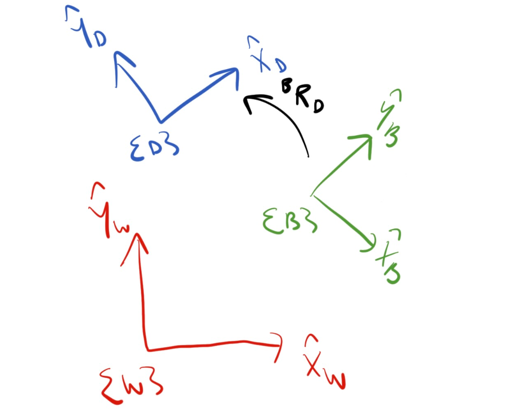

**Figure 2:** Depiction of the three fundamental reference frames when resolving orientation error.
 

If our desired orientation is different to our current orientation (${^W{\mathbf R}_B}\neq{^W{\mathbf R}_D}$), we will require some kind of adjustment in order to orchestrate the correct rotation, whereas if the two are aligned (${^W{\mathbf R}_B}={^W{\mathbf R}_D}$), we do not need to do anything. In general, we would like to find a desired orientation that is described in $\{B\}$, which tells us how the body frame needs to alter itself to meet our target configuration. Pre-multiplying  ${^W{\mathbf R}_D}$ by  ${^W{\mathbf R}_B^T}={^B{\mathbf R}_W}$ , we can map the desired orientation in $\{W\}$ to the desired orientation in $\{B\}$, which is given by 


$$\begin{array}{cc}{^B{\mathbf R}_D} = {^B{\mathbf R}_W}{^W{\mathbf R}_D}. \end{array}$$


Note again how the sub- and superscripts cancel out to yield the resulting rotation matrix.  ${^B{\mathbf R}_D}$ gives an indication of how the platform, described in the body-frame, should reorient itself in order to meet the inertial-frame objective of  ${^W{\mathbf R}_B}={^W{\mathbf R}_D}$ , and also can be thought of as the encoded orientation error as the body-frame orientation will always remain null. 

We can decode the resulting rotation matrix $\begin{array}{cc}{^B{\mathbf R}_D}  \end{array}$ to obtain a vector description of the error, which could take the form of exponential coordinates or Euler error. This 3-vector of angles can then be used to inform the robot platform of how to correct its orientation. 

#### 3.7.1.1 Euler error

Assuming the body-frame Euler errors are of interest, one can extract this information from $\begin{array}{cc}{^B{\mathbf R}_D}  \end{array}$ using


$$\begin{array}{cc}\phi_e = \arctan(\frac{r_{32}}{r_{33}})\end{array},$$



$$\begin{array}{cc}\theta_e = -\arcsin{r_{31},\end{array}$$



$$\begin{array}{cc}\psi_e = \arctan(\frac{r_{21}}{r_{11}}).\end{array}$$


The nature of Euler angles is that three sequential rotations are required, so the robot would need to make corrections in three discrete rotations, instead of one single rotation. This presents issues if time or energy optimality are important to the functionality of the system. Additionally, if the system is conditionally stable, having to perform three discrete rotations may not be feasible. Having said that, one can treat the three distinct rotations as one combined rotation if the rotational angles are sufficiently small such that  ${^B{\mathbf R}_D}\approx {\mathbf I}$ . This would mean that our quantification of the body-frame correction required is not perfectly accurate, but rather approximately accurate. As previously touched on, motion control does not naturally take place in ordered sequences, but rather lends itself to instantaneous gross motions. Euler angles can still be used in control systems that make use of 3D rotations if the correct considerations are made --- specifically, concerning the span of orientations that the system is expected to make use of. This makes the generalised Euler error largely unusable in a control sense (unless we intend to correct orientation errors in three disparate rotations). It would also not be possible to enforce this condition if the reference Euler angle experiences large step changes, as the Euler error would become large as a result of these steps. The Euler error formulation should therefore only be used for specific robotic platforms that experience small orientation errors (not to forget the other problem with singularities!). A fixed-wing airplane is a good example where using Euler errors is appropriate given the small angle behaviour during nominal flight conditions. This, however, would not be appropriate when speaking of fighter jets that perform aggressive and high angle-of-attack manoeuvres!

#### 3.7.1.2 Exponential coordinate error

Exponential coordinates are a natural way of expressing a rotation using the combination of a rotation vector and angle. Using our understanding of exponential coordinates, we can recover an error rotation vector from rotation matrix $\begin{array}{cc}{^B{\mathbf R}_D} = {^B{\mathbf R}_W}{^W{\mathbf R}_D} \end{array}$ using


$$\alpha_e=\cos^{-1}\left(\frac{1}{2}\left(\mathrm{tr}{^B{\bf R}_D}-1\right)\right),$$



$$\lfloor ^B\hat{\bf v}_e \rfloor = \frac{1}{2\sin{\alpha_e}}\left({^B{\bf R}_D}-{^B{\bf R}_D^T}\right).$$


Note that we are assuming $\alpha_e \neq \pi$ for sake of clarity. We can then combine the axis-angle form to give the 3-vector rotation error as

${^B{\bf e}}=\alpha_e^B\hat{\bf v}_e$.

This vector indicates the rotational displacement in $\{B\}$ required to align $^W{\bf R}_B$ to $^W{\bf R}_D$. Unlike the caveats of Euler error vectors, the approach above exactly describes the orientation error in $\{B\}$. This is very useful when controlling the attitude of rigid-body systems. The benefit in specifying the corrective action in the form of a scaled rotation vector is that we can theoretically adjust our orientation in one smooth rotational movement, as opposed to three disjointed rotations. Note that in stark comparison to the Euler formulation, we are also not limited to only handling small angle errors — the angular error can be arbitrarily large without issue.

### 3.7.2 Quaternion error formulation 

The quaternion structure can be used instead of a rotation matrix, which is appealing for minimising numerical operations. Recall that the unit quaternion encodes the information related to a rotation vector. That is, a single rotation about a defined axis. This is appealing from a control point of view as we can make orientation corrections simultaneously, without having to perform sequential operations or be subject to poor angle error approximations. For sake of convenience, the verbose quaternion structure is repeated below as 


$$\begin{array}{cc}{\mathbf q} = \left[\begin{array}{cc}    q_0 \\ q_x \\ q_y \\ q_z     \\ \end{array}\right] =    \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\ \sin{\frac{\alpha}{2}} \hat{\mathbf v}     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\     \sin{\frac{\alpha}{2}} v_x \\    \sin{\frac{\alpha}{2}} v_y \\    \sin{\frac{\alpha}{2}} v_z    \\ \end{array}\right].\\ \end{array}$$


Following a similar procedure that was used to determine the desired rotation matrix in $\{B\}$, our quaternion representation of our robot orientation in$\{W\}$ is ${^W{\mathbf q}_B}$ , and our desired quaternion in $\{W\}$ is ${^W{\mathbf q}_D}$ . Analogous to $\begin{array}{cc}{^B{\mathbf R}_D} = {^B{\mathbf R}_W}{^W{\mathbf R}_D} \end{array}$, our error quaternion in $\{B\}$ is given by


$$\begin{array}{cc}{^B{\mathbf q}_D} = {^B{\mathbf q}_W} \otimes {^W{\mathbf q}_D}.\end{array}$$


The equation above is beneficial based on the low number of element-wise arithmetic operations relative to multiplying two rotation matrices, but we can also now extract the exponential coordinates embedded in our quaternion formulation. Given the standard unit quaternion structure, our error quaternion can be written as


$$\begin{array}{cc}{^B{\mathbf q}_D} =    \left[\begin{array}{cc}    \cos{\frac{\alpha_e}{2}} \\ \sin{\frac{\alpha_e}{2}} {^B\hat{\bf v}_e}     \\ \end{array}\right],\end{array}$$


where  $\alpha_e$ corresponds to the rotation angle required to correct the orientation of the robot, and  $^B\hat{\bf v}_e$ refers to the rotation axis. Combined, the corresponding orientation error in $\{B\}$ is given by


$${^B{\bf e}}=\alpha_e^B\hat{\bf v}_e,$$


 which matches the result when converting rotation matrices to exponential coordinate errors. 

### 3.7.3 Control design using orientation error

The approaches presented above are crucial when controlling rigid-body robots, such as aerial vehicles. While the work presented here are generalisable to 3D rotations, there will be many cases when a robot is confined to a plane, in which case a single parameter is required to describe orientation error. We will see example of using orientation error in control loops in later chapters.